# **CONTROLE DISCRETO**

## MÉTODO DA ALOCAÇÃO DE POLOS

# _______________________________________________________________

# 1. Inicialização

## **1.1. VARIÁVEIS E CONSTANTES**

Unidades

precision = 4;
unit = vpasymunit('precision',precision);

Simbologia

s = vpasym('s') / unit.s;  % Frequência complexa s
r = sym('r',  'real');     % Variável de entrada de referência r
warning('off','symbolic:sym:sym:DeprecateExpressions')
REGULADOR      = -1;
SERVO_TIPO_0   =  0;
SERVO_TIPO_1   =  1;
COM_OBSERVADOR = true;

## **1.2. MODELO DO SERVOMECANISMO**

Parâmetros da planta

K   = 1.53   * unit.rad/(unit.V*unit.s)  % Ganho DC

$$K = 1.53\,\frac{\mathrm{rad}}{V\,s}$$

tau = 0.0254 * unit.s                    % Constante de tempo

$$tau = 0.0254\,s$$

Ts  = 0.001  * unit.s                    % Tempo de amostragem

$$Ts = 0.001\,s$$

Planta modelo simbólica contínua

G = K/(s*(tau*s+1))

$$G = \frac{1.53}{s\,\left(0.0254\,s+1.0\right)}\,\frac{\mathrm{rad}}{V}$$

## **1.3. ESPECIFICAÇÕES DE PROJETO**

Parâmetros desejados

goal.ess = 0;              % Erro de estado estacionário
goal.tp  = 0.20 * unit.s;  % Tempo máximo de pico
goal.Mp  = 5.0/100;        % Máximo sobressinal
dispsym('e_ss',goal.ess,precision)

$$e_{\mathrm{ss}}=0.0$$

dispsym('t_p', goal.tp, precision)

$$t_{p}=0.2$$

dispsym('M_p', goal.Mp, precision)

$$M_{p}=0.05$$

# _______________________________________________________________

# 2. Análise preliminar

## **2.1. FUNCÕES DE TRANSFERÊNCIA**

*2.1.1. PLANO CONTÍNUO*

Converte a função de transferência simbólica contínua para numérica contínua

Gs = sym2tf(G)


Gs =
 
      60.24
  -------------
  s^2 + 39.37 s
 
Continuous-time transfer function.



*2.1.2. PLANO DISCRETO*

Converte a função de transferência contínua para a pulsada

Gz = c2d(Gs,val(Ts)) % ou ...


Gz =
 
  2.973e-05 z + 2.934e-05
  -----------------------
  z^2 - 1.961 z + 0.9614
 
Sample time: 0.001 seconds
Discrete-time transfer function.



Gz = zpk(Gz)         % na forma de zeros, polos e ganho


Gz =
 
  2.9727e-05 (z+0.987)
  --------------------
    (z-1) (z-0.9614)
 
Sample time: 0.001 seconds
Discrete-time zero/pole/gain model.



## **2.2. ESPAÇO DE ESTADOS**

Ordem do sistema

n = order(Gs)

n = 2

Variáveis de estado

x  = sym('x',[1 n],  'real').'   % Normal    (sem integrador)

$$x = \left(\begin{array}{c} x_{1}\\ x_{2} \end{array}\right)$$

xi = sym('x',[1 n+1],'real').'   % Expandida (com integrador)

$$xi = \left(\begin{array}{c} x_{1}\\ x_{2}\\ x_{3} \end{array}\right)$$

Saída

y = sym('y','real').'

$$y = y$$

*2.2.1. PLANO CONTÍNUO*

Converte a função de transferência contínua para o espaço de estados contínuo na forma canônica controlável

[A,B,C,D] = tf2ss2(Gs);
sys = ss(A,B,C,D);
sseqdisp('t',A,'A',B,'B',C,'C',D,'D','u',precision)

$$\frac{\partial }{\partial t}x\left(t\right)=A\,x\left(t\right)+B\,u\left(t\right)$$

$$y\left(t\right)=C\,x\left(t\right)$$

$$A=\left(\begin{array}{cc} 0 & 1.0\\ 0 & -39.37 \end{array}\right)$$

$$B=\left(\begin{array}{c} 0\\ 1.0 \end{array}\right)$$

$$C=\left(\begin{array}{cc} 60.24 & 0 \end{array}\right)$$

Um resultado equivalente pode ser obtido pelos comandos do MATLAB abaixo, onde as variáveis de estado são definidas de forma inversa

[b,a] = tfdata(Gs);
[A_eq,B_eq,C_eq,D_eq] = tf2ss(b{:},a{:});
sys_eq = ss(A_eq,B_eq,C_eq,D_eq);
sseqdisp('t',A_eq,'A_eq',B_eq,'B_eq',C_eq,'C_eq',D_eq,'D_eq','u',precision)

$$\frac{\partial }{\partial t}x\left(t\right)=A_{\mathrm{eq}}\,x\left(t\right)+B_{\mathrm{eq}}\,u\left(t\right)$$

$$y\left(t\right)=C_{\mathrm{eq}}\,x\left(t\right)$$

$$A_{\mathrm{eq}}=\left(\begin{array}{cc} -39.37 & 0\\ 1.0 & 0 \end{array}\right)$$

$$B_{\mathrm{eq}}=\left(\begin{array}{c} 1.0\\ 0 \end{array}\right)$$

$$C_{\mathrm{eq}}=\left(\begin{array}{cc} 0 & 60.24 \end{array}\right)$$

*2.2.2. PLANO DISCRETO*

Converte a função de transferência pulsada para o espaço de estados discreto na forma canônica controlável

[Ad,Bd,Cd,Dd] = tf2ss2(Gz);
sysd = ss(Ad,Bd,Cd,Dd,val(Ts));
sseqdisp('k',Ad,'A_d',Bd,'B_d',Cd,'C_d',Dd,'D_d','u',precision)

$$x\left(k+1\right)=A_{d}\,x\left(k\right)+B_{d}\,u\left(k\right)$$

$$y\left(k+1\right)=C_{d}\,x\left(k\right)$$

$$A_{d}=\left(\begin{array}{cc} 0 & 1.0\\ -0.9614 & 1.961 \end{array}\right)$$

$$B_{d}=\left(\begin{array}{c} 0\\ 1.0 \end{array}\right)$$

$$C_{d}=\left(\begin{array}{cc} 2.934\,10^{-5} & 2.973\,10^{-5} \end{array}\right)$$

Um resultado equivalente pode ser obtido pelos comandos do MATLAB abaixo, onde as variáveis de estado são definidas de forma inversa

[bd,ad] = tfdata(Gz);
[Ad_eq,Bd_eq,Cd_eq,Dd_eq] = tf2ss(bd{:},ad{:});
sysd_eq = ss(Ad_eq,Bd_eq,Cd_eq,Dd_eq,val(Ts));
sseqdisp('k',Ad_eq,'A_deq',Bd_eq,'B_deq',Cd_eq,'C_deq',Dd_eq,'D_deq','u',precision)

$$x\left(k+1\right)=A_{\mathrm{deq}}\,x\left(k\right)+B_{\mathrm{deq}}\,u\left(k\right)$$

$$y\left(k+1\right)=C_{\mathrm{deq}}\,x\left(k\right)$$

$$A_{\mathrm{deq}}=\left(\begin{array}{cc} 1.961 & -0.9614\\ 1.0 & 0 \end{array}\right)$$

$$B_{\mathrm{deq}}=\left(\begin{array}{c} 1.0\\ 0 \end{array}\right)$$

$$C_{\mathrm{deq}}=\left(\begin{array}{cc} 2.973\,10^{-5} & 2.934\,10^{-5} \end{array}\right)$$

Aumenta o espaço de estados adicionando uma variável integradora do erro

[Adi,Bdi,Cdi,Ddi] = incss(Ad,Bd,Cd,Dd);
sysdi = ss(Adi,Bdi,Cdi,Ddi,val(Ts));
sseqdisp('k',Adi,'A_di',Bdi,'B_di',Cdi,'C_di',Ddi,'D_di','u',precision)

$$x\left(k+1\right)=A_{\mathrm{di}}\,x\left(k\right)+B_{\mathrm{di}}\,u\left(k\right)$$

$$y\left(k+1\right)=C_{\mathrm{di}}\,x\left(k\right)$$

$$A_{\mathrm{di}}=\left(\begin{array}{ccc} 0 & 1.0 & 0\\ -0.9614 & 1.961 & 0\\ -2.934\,10^{-5} & -2.973\,10^{-5} & 1.0 \end{array}\right)$$

$$B_{\mathrm{di}}=\left(\begin{array}{c} 0\\ 1.0\\ 0 \end{array}\right)$$

$$C_{\mathrm{di}}=\left(\begin{array}{ccc} 2.934\,10^{-5} & 2.973\,10^{-5} & 0 \end{array}\right)$$

## 2.3. CONTROLABILIDADE

*2.3.1. PLANO CONTÍNUO*

Calcula a matriz de controlabilidade de Kalman contínua

Co = ctrb2(A,B)

Co =          0    1.0000
    1.0000  -39.3701


O mesmo resultado pode ser obtido pelo comando do MATLAB

Co = ctrb(A,B)

Co =          0    1.0000
    1.0000  -39.3701


Verifica se o sistema contínuo é controlável

assert(isctrb(Co),'O sistema contínuo não é controlável')

*2.3.2. PLANO DISCRETO*

Calcula a matriz de controlabilidade de Kalman discreta para a planta sem e com o integrador

Cod  = ctrb2(Ad,Bd)

Cod =          0    1.0000
    1.0000    1.9614


Codi = ctrb2(Adi,Bdi)

Codi =          0    1.0000    1.9614
    1.0000    1.9614    2.8857
         0   -0.0000   -0.0001


Os mesmos resultados podem ser obtidos pelo comando do MATLAB

Cod  = ctrb(Ad,Bd)

Cod =          0    1.0000
    1.0000    1.9614


Codi = ctrb(Adi,Bdi)

Codi =          0    1.0000    1.9614
    1.0000    1.9614    2.8857
         0   -0.0000   -0.0001


Verifica se os sistemas discretos são controláveis (quando sem o integrador, o resultado deve ser o mesmo do contínuo)

assert(isctrb(Cod), 'O sistema discreto não é controlável')
assert(isctrb(Codi),'O sistema discreto com integrador não é controlável')

## 2.4. OBSERVABILIDADE

*2.4.1. PLANO CONTÍNUO*

Calcula a matriz de observabilidade de Kalman contínua

Ob = obsv2(A,C)

Ob =    60.2362         0
         0   60.2362


O mesmo resultado pode ser obtido pelo comando do MATLAB

Ob = obsv(A,C)

Ob =    60.2362         0
         0   60.2362


Verifica se o sistema contínuo é observável

[TF,mc] = isobsv(Ob);
if     TF,    disp('O sistema é observável de ordem plena')
elseif mc, warning('O sistema é parcialmente observável')
else,        error('O sistema não é observável'), end

*2.4.2. PLANO DISCRETO*

Calcula a matriz de observabilidade de Kalman discreta para a planta sem e com o integrador

Obd  = obsv2(Ad,Cd)

Obd =    1.0e-04 *

    0.2934    0.2973
   -0.2858    0.8764


Obdi = obsv2(Adi,Cdi)

Obdi =    1.0e-03 *

    0.0293    0.0297         0
   -0.0286    0.0876         0
   -0.0843    0.1433         0


Os mesmos resultados podem ser obtidos pelo comando do MATLAB

Obd  = obsv(Ad,Cd)

Obd =    1.0e-04 *

    0.2934    0.2973
   -0.2858    0.8764


Obdi = obsv(Adi,Cdi)

Obdi =    1.0e-03 *

    0.0293    0.0297         0
   -0.0286    0.0876         0
   -0.0843    0.1433         0


Verifica se os sistemas discretos são observáveis (quando sem o integrador, o resultado deve ser o mesmo do contínuo)

[TF,md] = isobsv(Obd);
if     TF,    disp('O sistema é observável de ordem plena')
elseif md, warning('O sistema é parcialmente observável')
else,        error('O sistema não é observável'), end


[TF,mi] = isobsv(Obdi);
if     TF,    disp('O sistema com integrador é observável de ordem plena')
elseif mi, warning('O sistema com integrador é parcialmente observável')
else,        error('O sistema com integrador não é observável'), end

# _______________________________________________________________

# 3. Controladores por realimentação de estados

## **3.1. RESPOSTA DE CONTROLE DESEJADA**

*3.1.1. PLANO CONTÍNUO*

Coeficiente de amortecimento e frequência natural não amortecida para o tempo de pico e máximo sobressinal desejados em uma resposta de segunda ordem

[goal.zeta, goal.wn] = secordparam(goal.tp,goal.Mp,precision);
dispsym('zeta',   goal.zeta,precision)

$$\zeta =0.6901$$

dispsym('omega_n',goal.wn,  precision)

$$\omega_{n}=21.7$$

Coeficientes e polos do polinômio característico para a solução p = σ ± jωd

[goal.pc, goal.p, goal.sigma, goal.wd] = secord2poles(goal.zeta,goal.wn);
dispsym('pc',     goal.pc,   precision)

$$\mathrm{pc}=\left(\begin{array}{ccc} 1.0 & 29.96 & 471.1 \end{array}\right)$$

dispsym('p',      goal.p',   precision)

$$p=\left(\begin{array}{c} -14.98-15.71\,\mathrm{i}\\ -14.98+15.71\,\mathrm{i} \end{array}\right)$$

dispsym('sigma',  goal.sigma,precision)

$$\sigma =14.98$$

dispsym('omega_d',goal.wd,   precision)

$$\omega_{d}=15.71$$

*3.1.2. PLANO DISCRETO*

Transformação dos polos desejados no plano contínuo para o plano discreto sem integrador

[goal.zpc, goal.zp] = c2dpoles(goal.p,Ts);
dispsym('z_pc',goal.zpc,precision)

$$z_{\mathrm{pc}}=\left(\begin{array}{ccc} 1.0 & -1.97 & 0.9705 \end{array}\right)$$

dispsym('z_p', goal.zp',precision)

$$z_{p}=\left(\begin{array}{c} 0.985-0.01547\,\mathrm{i}\\ 0.985+0.01547\,\mathrm{i} \end{array}\right)$$

Adição de um polo recessivo para o plano discreto com integrador

Krc = 10;                                     % Fator de recessão do polo adicional
[~,zprc]  = c2dpoles(Krc*real(goal.p(1)),Ts)  % Polo recessivo

zprc = 0.8609

goal.zpi  = [goal.zp, zprc];                  % Completa os polos
goal.zpci = poly(goal.zpi);
dispsym('z_pci',goal.zpci,precision)

$$z_{\mathrm{pci}}=\left(\begin{array}{cccc} 1.0 & -2.831 & 2.666 & -0.8355 \end{array}\right)$$

dispsym('z_pi', goal.zpi',precision)

$$z_{\pi }=\left(\begin{array}{c} 0.985-0.01547\,\mathrm{i}\\ 0.985+0.01547\,\mathrm{i}\\ 0.8609 \end{array}\right)$$

Polos na origem para o controlador deadbeat

goal.zpb  = zeros(1,length(goal.zp));
goal.zpcb = poly(goal.zpb);
dispsym('z_pcb',goal.zpcb,precision)

$$z_{\mathrm{pcb}}=\left(\begin{array}{ccc} 1.0 & 0 & 0 \end{array}\right)$$

dispsym('z_pb', goal.zpb',precision)

$$z_{\mathrm{pb}}=\left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

## 3.2. GANHOS DE REALIMENTAÇÃO

*3.2.1. REGULADOR*

Determina o vetor de ganhos da realimentação de estados pela Fórmula de Ackermann

Kr = acker2(Ad,Bd,goal.zp)

Kr =     0.0091   -0.0086


O mesmo resultado pode ser obtido pelos comandos do MATLAB

Kr = acker(Ad,Bd,goal.zp)  % ... ou

Kr =     0.0091   -0.0086


Kr = place(Ad,Bd,goal.zp)  % para o caso de um controle robusto

Kr =     0.0091   -0.0086


*3.2.2. SERVOSSISTEMA DO TIPO 1*

Vetor de ganhos é o mesmo de um regulador

Kc = Kr

Kc =     0.0091   -0.0086


*3.2.3. SERVOSSISTEMA COM INTEGRADOR*

Determina o vetor de ganhos da realimentação de estados pela Fórmula de Ackermann

Ki = acker2(Adi,Bdi,goal.zpi)

Ki =    -0.1259    0.1305   -1.0930


O mesmo resultado pode ser obtido pelos comandos do MATLAB

Ki = acker(Adi,Bdi,goal.zpi)  % ... ou

Ki =    -0.1259    0.1305   -1.0930


Ki = place(Adi,Bdi,goal.zpi)  % para o caso de um controle robusto

Ki =    -0.1259    0.1305   -1.0930


*3.2.4. DEADBEAT*

Determina o vetor de ganhos da realimentação de estados pela Fórmula de Ackermann

Kb = acker2(Ad,Bd,goal.zpb)

Kb =    -0.9614    1.9614


O mesmo resultado pode ser obtido pelos comandos do MATLAB

Kb = acker(Ad,Bd,goal.zpb)

Kb =    -0.9614    1.9614


## 3.3. ESPAÇO DE ESTADOS COM CONTROLADOR

*3.3.1. REGULADOR*

Matrizes do sistema discreto com o regulador

[Adr,Bdr,Cdr,Ddr,Fr] = redss(Ad,Bd,Cd,Dd,Kr,REGULADOR);
sysd_regl = ss(Adr,Bdr,Cdr,Ddr,val(Ts));
sseqdisp('k',Adr,'A_dr',Bdr,'B_dr',Cdr,'C_dr',Ddr,'D_dr','u',precision)

$$x\left(k+1\right)=A_{\mathrm{dr}}\,x\left(k\right)$$

$$y\left(k+1\right)=C_{\mathrm{dr}}\,x\left(k\right)$$

$$A_{\mathrm{dr}}=\left(\begin{array}{cc} 0 & 1.0\\ -0.9705 & 1.97 \end{array}\right)$$

$$C_{\mathrm{dr}}=\left(\begin{array}{cc} 2.934\,10^{-5} & 2.973\,10^{-5} \end{array}\right)$$

A solução do regulador é dada por

ur = -Kr*x + Fr*r;
ur = vpa(ur,precision)

$$ur = 0.008628\,x_{2}-0.009092\,x_{1}$$

*3.3.2. SERVOSSISTEMA DO TIPO 1*

Matrizes do sistema discreto com o servossistema do tipo 1

[Adc,Bdc,Cdc,Ddc,Fc] = redss(Ad,Bd,Cd,Dd,Kc,SERVO_TIPO_1);
sysd_ctrl = ss(Adc,Bdc,Cdc,Ddc,val(Ts));
sseqdisp('k',Adc,'A_dc',Bdc,'B_dc',Cdc,'C_dc',Ddc,'D_dc','r',precision)

$$x\left(k+1\right)=A_{\mathrm{dc}}\,x\left(k\right)+B_{\mathrm{dc}}\,r\left(k\right)$$

$$y\left(k+1\right)=C_{\mathrm{dc}}\,x\left(k\right)$$

$$A_{\mathrm{dc}}=\left(\begin{array}{cc} 0 & 1.0\\ -0.9705 & 1.97 \end{array}\right)$$

$$B_{\mathrm{dc}}=\left(\begin{array}{c} 0\\ 7.857 \end{array}\right)$$

$$C_{\mathrm{dc}}=\left(\begin{array}{cc} 2.934\,10^{-5} & 2.973\,10^{-5} \end{array}\right)$$

A solução do servossistema do tipo 1 é dada por

uc = -Kc*x + Fc*r;
uc = vpa(uc,precision)

$$uc = 7.857\,r-0.009092\,x_{1}+0.008628\,x_{2}$$

*3.3.3. SERVOSSISTEMA COM INTEGRADOR*

Matrizes do sistema discreto com o servossistema com integrador

[Adic,Bdic,Cdic,Ddic,Fic] = redss(Ad,Bd,Cd,Dd,Ki,SERVO_TIPO_0);
sysdi_ctrl = ss(Adic,Bdic,Cdic,Ddic,val(Ts));
sseqdisp('k',Adic,'A_dic',Bdic,'B_dic',Cdic,'C_dic',Ddic,'D_dic','r',precision)

$$x\left(k+1\right)=A_{\mathrm{dic}}\,x\left(k\right)+B_{\mathrm{dic}}\,r\left(k\right)$$

$$y\left(k+1\right)=C_{\mathrm{dic}}\,x\left(k\right)$$

$$A_{\mathrm{dic}}=\left(\begin{array}{ccc} 0 & 1.0 & 0\\ -0.8355 & 1.831 & 1.093\\ -2.934\,10^{-5} & -2.973\,10^{-5} & 1.0 \end{array}\right)$$

$$B_{\mathrm{dic}}=\left(\begin{array}{c} 0\\ 0\\ 1.0 \end{array}\right)$$

$$C_{\mathrm{dic}}=\left(\begin{array}{ccc} 2.934\,10^{-5} & 2.973\,10^{-5} & 0 \end{array}\right)$$

A solução do servossistema do tipo 1 é dada por

uic = -Ki*xi;
uic = vpa(uic,precision)

$$uic = 0.1259\,x_{1}-0.1305\,x_{2}+1.093\,x_{3}$$

*3.3.4. DEADBEAT*

Matrizes do sistema discreto com o controlador deadbeat

[Adbc,Bdbc,Cdbc,Ddbc,Fbc] = redss(Ad,Bd,Cd,Dd,Kb,REGULADOR);
sysdb_ctrl = ss(Adbc,Bdbc,Cdbc,Ddbc,val(Ts));
sseqdisp('k',Adbc,'A_dbc',Bdbc,'B_dbc',Cdbc,'C_dbc',Ddbc,'D_dbc','r',precision)

$$x\left(k+1\right)=A_{\mathrm{dbc}}\,x\left(k\right)$$

$$y\left(k+1\right)=C_{\mathrm{dbc}}\,x\left(k\right)$$

$$A_{\mathrm{dbc}}=\left(\begin{array}{cc} 0 & 1.0\\ 0 & 0 \end{array}\right)$$

$$C_{\mathrm{dbc}}=\left(\begin{array}{cc} 2.934\,10^{-5} & 2.973\,10^{-5} \end{array}\right)$$

A solução do deadbeat é dada por

ubc = -Kb*x + Fbc*r;
ubc = vpa(ubc,precision)

$$ubc = 0.9614\,x_{1}-1.961\,x_{2}$$

## 3.4. RESPOSTAS SEM E COM CONTROLADOR

Amplitude do sinal de entrada

R = pi/8  % Degrau unitário

R = 0.3927

Tempo final da simulação

tfinal = 1/0.4 * unit.s

$$tfinal = 2.5\,s$$

Estado inicial

x0 = R*ones(n,1)/sysd.C(1)/2

x0 =    1.0e+03 *

    6.6924
    6.6924


Analiza as respostas do sistema sem controlador

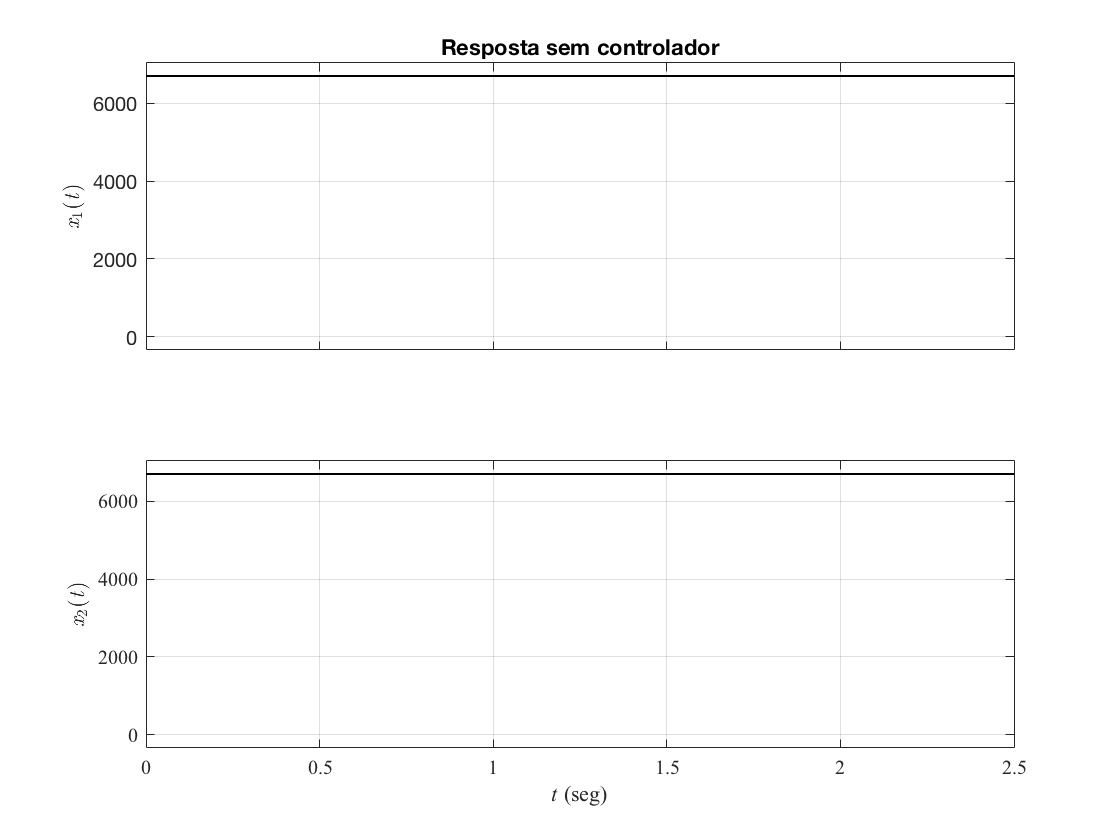

[X,h] = resposta(sysd,x0,tfinal);
title(h.Children(end),'Resposta sem controlador')

*3.4.1. REGULADOR*

Estado inicial

x0r = R*ones(n,1)/sysd_regl.C(1)/2

x0r =    1.0e+03 *

    6.6924
    6.6924


Analiza as respostas do sistema com regulador

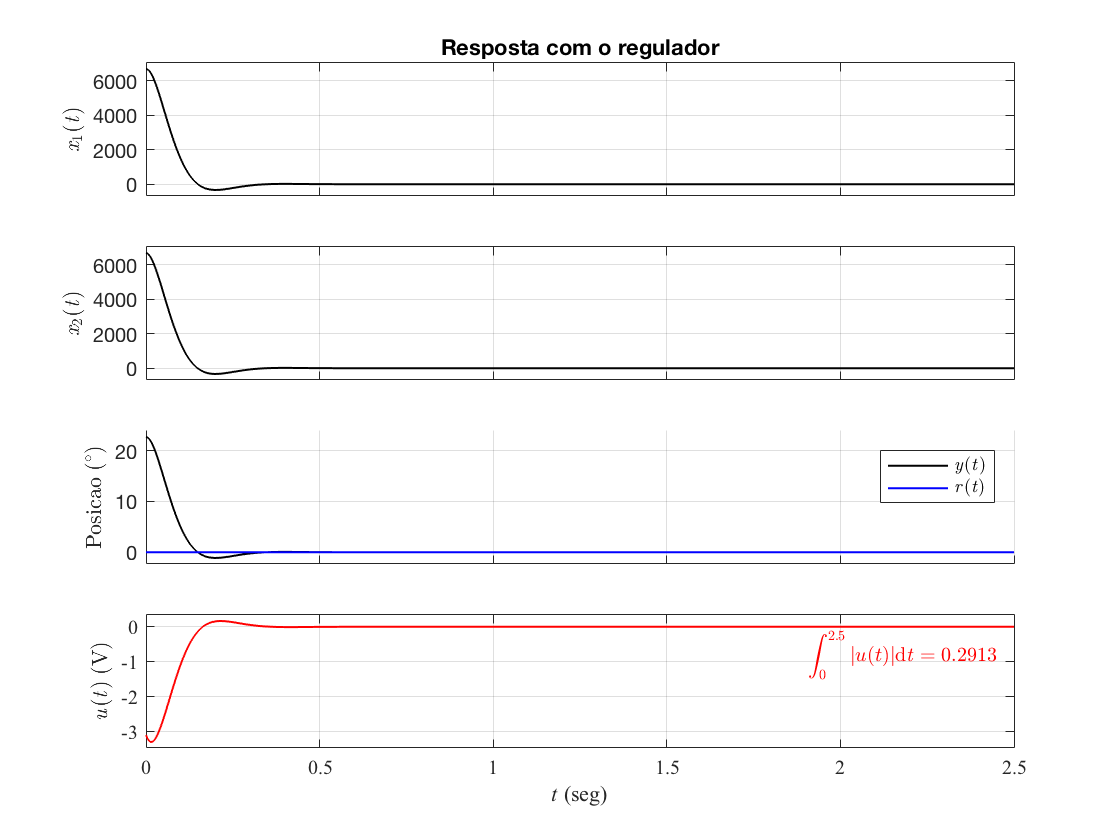

[Xr,Yr,Ur,hr] = resposta(sysd_regl,x0r,tfinal,ur);
title(hr.Children(end),'Resposta com o regulador')

*3.4.2. SERVOSSISTEMA DO TIPO 1*

Estado inicial

x0c = zeros(n,1)

x0c =      0
     0


Analiza as respostas do sistema com servossistema do tipo 1

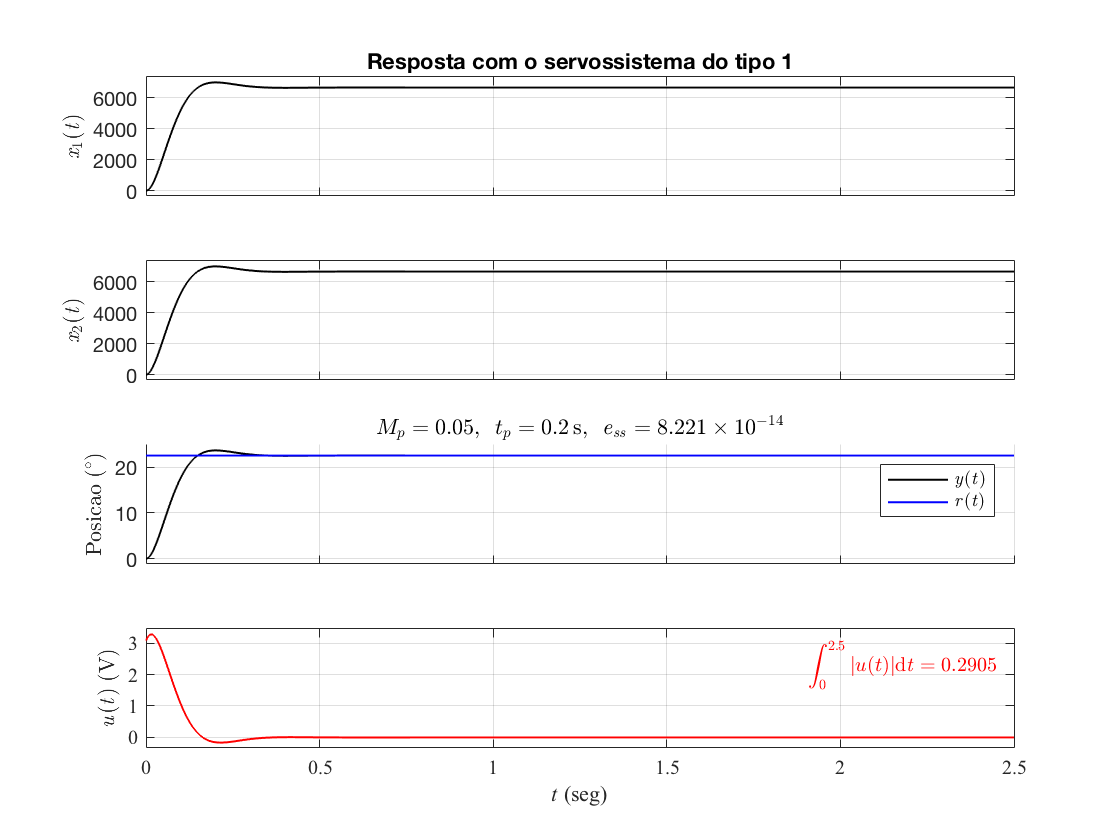

[Xc,Yc,Uc,Rc,hc] = resposta(sysd_ctrl,x0c,tfinal,uc,R);
title(hc.Children(end),'Resposta com o servossistema do tipo 1')

*3.4.3. SERVOSSISTEMA COM INTEGRADOR*

Estado inicial

x0i = zeros(n+1,1)

x0i =      0
     0
     0


Analiza as respostas do sistema com servossistema com integrador

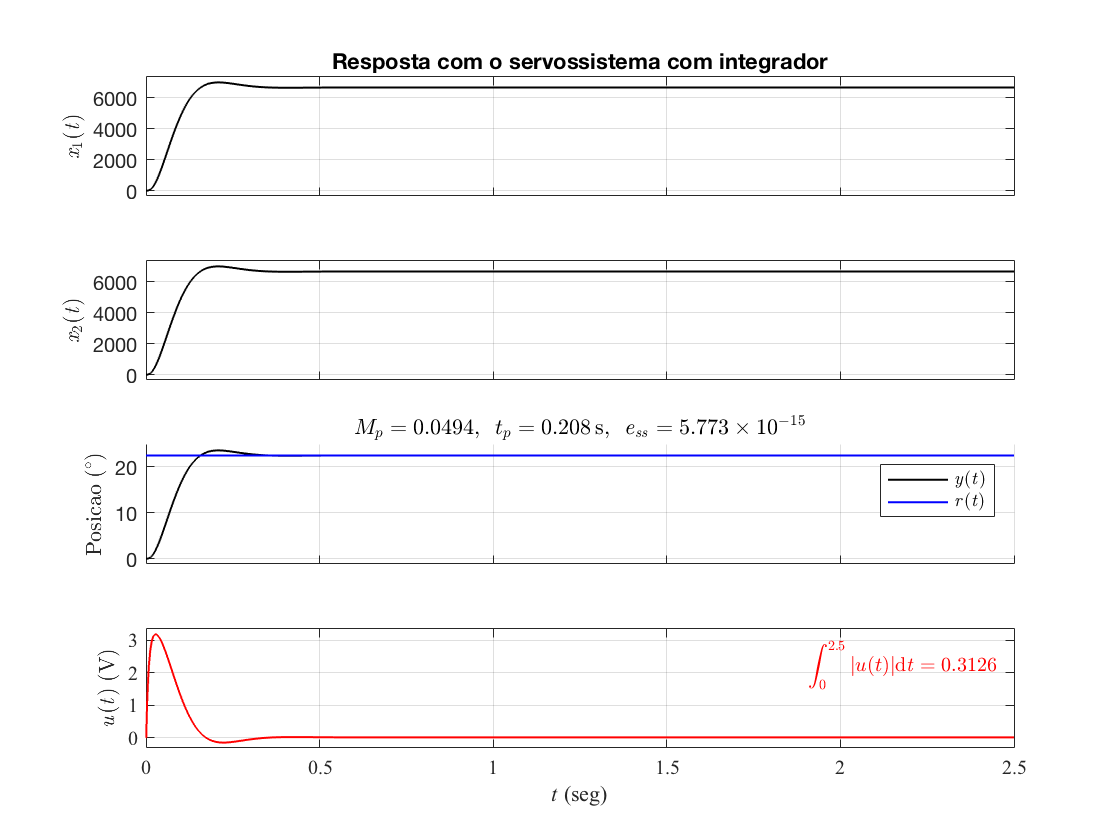

[Xic,Yic,Uic,Ric,hic] = resposta(sysdi_ctrl,x0i,tfinal,uic,R);
title(hic.Children(end),'Resposta com o servossistema com integrador')

*3.4.4. DEADBEAT*

Estado inicial

x0b = R*ones(n,1)/sysdb_ctrl.C(1)/2

x0b =    1.0e+03 *

    6.6924
    6.6924


Analiza as respostas do sistema com controlador deadbeat

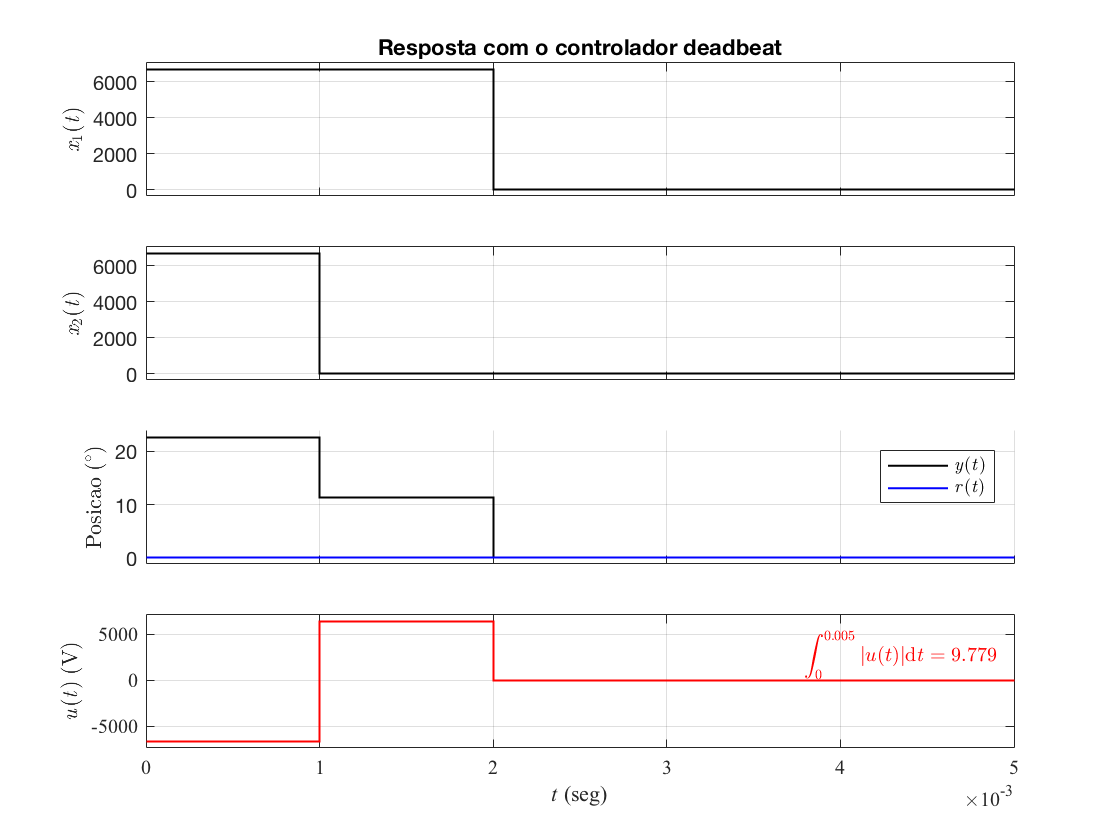

[Xbc,Ybc,Ubc,hbc] = resposta(sysdb_ctrl,x0b,5*Ts,ubc);
title(hbc.Children(end),'Resposta com o controlador deadbeat')

# _______________________________________________________________

# 4. Observadores de estados

## **4.1. RESPOSTA DE OBSERVAÇÃO DESEJADA**

Amplificação dos polos do controle discreto sem integrador nos polos do observador para uma observação mais rápida

Kao = 3;                             % Fator de amplificação dos polos do observador
goal.zo  = exp(Kao*log(goal.zp));    % Polos do observador
goal.zoc = poly(goal.zo);            % Polinômio característico
dispsym('z_oc',goal.zoc,precision)

$$z_{\mathrm{oc}}=\left(\begin{array}{ccc} 1.0 & -1.91 & 0.914 \end{array}\right)$$

dispsym('z_o', goal.zo',precision)

$$z_{o}=\left(\begin{array}{c} 0.955-0.04504\,\mathrm{i}\\ 0.955+0.04504\,\mathrm{i} \end{array}\right)$$

O mesmo é feito para o plano discreto com integrador

goal.zoi  = exp(Kao*log(goal.zpi));    % Polos do observador
goal.zoic = poly(goal.zoi);            % Polinômio característico
dispsym('z_oci',goal.zoic,precision)

$$z_{\mathrm{oci}}=\left(\begin{array}{cccc} 1.0 & -2.548 & 2.133 & -0.5832 \end{array}\right)$$

dispsym('z_oi', goal.zoi',precision)

$$z_{\mathrm{oi}}=\left(\begin{array}{c} 0.955-0.04504\,\mathrm{i}\\ 0.955+0.04504\,\mathrm{i}\\ 0.638 \end{array}\right)$$

Polos na origem para o controlador deadbeat

goal.zob  = zeros(1,length(goal.zp));
goal.zocb = poly(goal.zob);
dispsym('z_ocb',goal.zocb,precision)

$$z_{\mathrm{ocb}}=\left(\begin{array}{ccc} 1.0 & 0 & 0 \end{array}\right)$$

dispsym('z_ob', goal.zob',precision)

$$z_{\mathrm{ob}}=\left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

## 4.2. GANHOS DE OBSERVAÇÃO

*4.2.1. REGULADOR*

Determina o vetor de ganhos da observação de estados pela Fórmula de Ackermann

Kor = acker2(Ad,Cd,goal.zo)

Kor =   852.2373
  887.9638


O mesmo resultado pode ser obtido pelos comandos do MATLAB

Kor = acker(Ad',Cd',goal.zo).'  % ... ou

Kor =   852.2373
  887.9638


Kor = place(Ad',Cd',goal.zo).'  % para o caso de um controle robusto

Kor =   852.2373
  887.9638


*4.2.2. SERVOSSISTEMA DO TIPO 1*

Vetor de ganhos é o mesmo de um regulador

Koc = Kor

Koc =   852.2373
  887.9638


*4.2.3. SERVOSSISTEMA COM INTEGRADOR*

Vetor de ganhos é o mesmo de um regulador

Koi = Kor

Koi =   852.2373
  887.9638


*4.2.4. DEADBEAT*

Determina o vetor de ganhos da realimentação de estados pela Fórmula de Ackermann

Kob = acker2(Ad,Cd,goal.zob)

Kob =    1.0e+04 *

    2.5175
    4.1134


## 4.3. ESPAÇO DE ESTADOS COM OBSERVADOR

*4.3.1. OBSERVADOR*

Matrizes do sistema discreto com o observador

[Ador,Bdor,Cdor,Ddor,For] = redss(Ad,Bd,Cd,Dd,Kr,REGULADOR,Kor);
sysdo_regl = ss(Ador,Bdor,Cdor,Ddor,val(Ts));
sseqdisp('k',Ador,'A_dor',Bdor,'B_dor',Cdor,'C_dor',Ddor,'D_dor','u',precision)

$$x\left(k+1\right)=A_{\mathrm{dor}}\,x\left(k\right)$$

$$y\left(k+1\right)=C_{\mathrm{dor}}\,x\left(k\right)$$

$$A_{\mathrm{dor}}=\left(\begin{array}{cccc} 0 & 1.0 & 0 & 0\\ -0.9705 & 1.97 & -0.009092 & 0.008628\\ 0 & 0 & -0.025 & 0.9747\\ 0 & 0 & -0.9874 & 1.935 \end{array}\right)$$

$$C_{\mathrm{dor}}=\left(\begin{array}{cccc} 2.934\,10^{-5} & 2.973\,10^{-5} & 0 & 0 \end{array}\right)$$

A solução do regulador é dada por

uor = -Kor*y;
uor = vpa(uor,precision)

$$uor = \left(\begin{array}{c} -852.2\,y\\ -888.0\,y \end{array}\right)$$

*4.3.2. SERVOSSISTEMA DO TIPO 1*

Matrizes do sistema discreto com o servossistema do tipo 1

[Adoc,Bdoc,Cdoc,Ddoc,Foc] = redss(Ad,Bd,Cd,Dd,Kc,SERVO_TIPO_1,Koc);
sysdo_ctrl = ss(Adoc,Bdoc,Cdoc,Ddoc,val(Ts));
sseqdisp('k',Adoc,'A_dc',Bdoc,'B_doc',Cdoc,'C_doc',Ddoc,'D_doc','r',precision)

$$x\left(k+1\right)=A_{\mathrm{dc}}\,x\left(k\right)+B_{\mathrm{doc}}\,r\left(k\right)$$

$$y\left(k+1\right)=C_{\mathrm{doc}}\,x\left(k\right)$$

$$A_{\mathrm{dc}}=\left(\begin{array}{cccc} 0 & 1.0 & 0 & 0\\ -0.9705 & 1.97 & -0.009092 & 0.008628\\ 0 & 0 & -0.025 & 0.9747\\ 0 & 0 & -0.9874 & 1.935 \end{array}\right)$$

$$B_{\mathrm{doc}}=\left(\begin{array}{c} 0\\ 7.857\\ 0\\ 0 \end{array}\right)$$

$$C_{\mathrm{doc}}=\left(\begin{array}{cccc} 2.934\,10^{-5} & 2.973\,10^{-5} & 0 & 0 \end{array}\right)$$

A solução do servossistema do tipo 1 é dada por

uoc = -Koc*y;
uoc = vpa(uoc,precision)

$$uoc = \left(\begin{array}{c} -852.2\,y\\ -888.0\,y \end{array}\right)$$

*4.3.3. SERVOSSISTEMA COM INTEGRADOR*

Matrizes do sistema discreto com o servossistema com integrador

[Adoic,Bdoic,Cdoic,Ddoic,Foic] = redss(Ad,Bd,Cd,Dd,Ki,SERVO_TIPO_0,Koi);
sysdoi_ctrl = ss(Adoic,Bdoic,Cdoic,Ddoic,val(Ts));
sseqdisp('k',Adoic,'A_doic',Bdoic,'B_doic',Cdoic,'C_doic',Ddoic,'D_doic','r',precision)

$$x\left(k+1\right)=A_{\mathrm{doic}}\,x\left(k\right)+B_{\mathrm{doic}}\,r\left(k\right)$$

$$y\left(k+1\right)=C_{\mathrm{doic}}\,x\left(k\right)$$

$$A_{\mathrm{doic}}=\left(\begin{array}{ccccc} 0 & 1.0 & 0 & 0 & 0\\ -0.8355 & 1.831 & 0.1259 & -0.1305 & 1.093\\ 0 & 0 & -0.025 & 0.9747 & 0\\ 0 & 0 & -0.9874 & 1.935 & 0\\ -2.934\,10^{-5} & -2.973\,10^{-5} & 0 & 0 & 1.0 \end{array}\right)$$

$$B_{\mathrm{doic}}=\left(\begin{array}{c} 0\\ 0\\ 0\\ 0\\ 1.0 \end{array}\right)$$

$$C_{\mathrm{doic}}=\left(\begin{array}{ccccc} 2.934\,10^{-5} & 2.973\,10^{-5} & 0 & 0 & 0 \end{array}\right)$$

A solução do servossistema do tipo 1 é dada por

uoic = -Koi*y;
uoic = vpa(uoic,precision)

$$uoic = \left(\begin{array}{c} -852.2\,y\\ -888.0\,y \end{array}\right)$$

*4.3.4. DEADBEAT*

Matrizes do sistema discreto com o controlador deadbeat

[Adobc,Bdobc,Cdobc,Ddobc,Fobc] = redss(Ad,Bd,Cd,Dd,Kb,REGULADOR,Kob);
sysdob_ctrl = ss(Adobc,Bdobc,Cdobc,Ddobc,val(Ts));
sseqdisp('k',Adobc,'A_dobc',Bdobc,'B_dobc',Cdobc,'C_dobc',Ddobc,'D_dobc','r',precision)

$$x\left(k+1\right)=A_{\mathrm{dobc}}\,x\left(k\right)$$

$$y\left(k+1\right)=C_{\mathrm{dobc}}\,x\left(k\right)$$

$$A_{\mathrm{dobc}}=\left(\begin{array}{cccc} 0 & 1.0 & 0 & 0\\ 0 & 0 & 0.9614 & -1.961\\ 0 & 0 & -0.7386 & 0.2516\\ 0 & 0 & -2.168 & 0.7386 \end{array}\right)$$

$$C_{\mathrm{dobc}}=\left(\begin{array}{cccc} 2.934\,10^{-5} & 2.973\,10^{-5} & 0 & 0 \end{array}\right)$$

A solução do deadbeat é dada por

uobc = -Kob*y;
uobc = vpa(uobc,precision)

$$uobc = \left(\begin{array}{c} -25199.0\,y\\ -41133.0\,y \end{array}\right)$$

## 4.4. RESPOSTAS COM OBSERVADOR

Amplitude do sinal de entrada

R = pi/8  % Degrau unitário

R = 0.3927

Tempo final da simulação

tfinal = 1/0.4 * unit.s

$$tfinal = 2.5\,s$$

*4.4.1. REGULADOR*

Estado inicial (definido aqui como [x_real; x_estimado])

x0or = R*ones(n,1)/sysd_regl.C(1)/2;
x0or = [eye(n), zeros(n); zeros(n), -eye(n)] * repmat(x0or,n,1)

x0or =    1.0e+03 *

    6.6924
    6.6924
   -6.6924
   -6.6924


Analiza as respostas do sistema com regulador

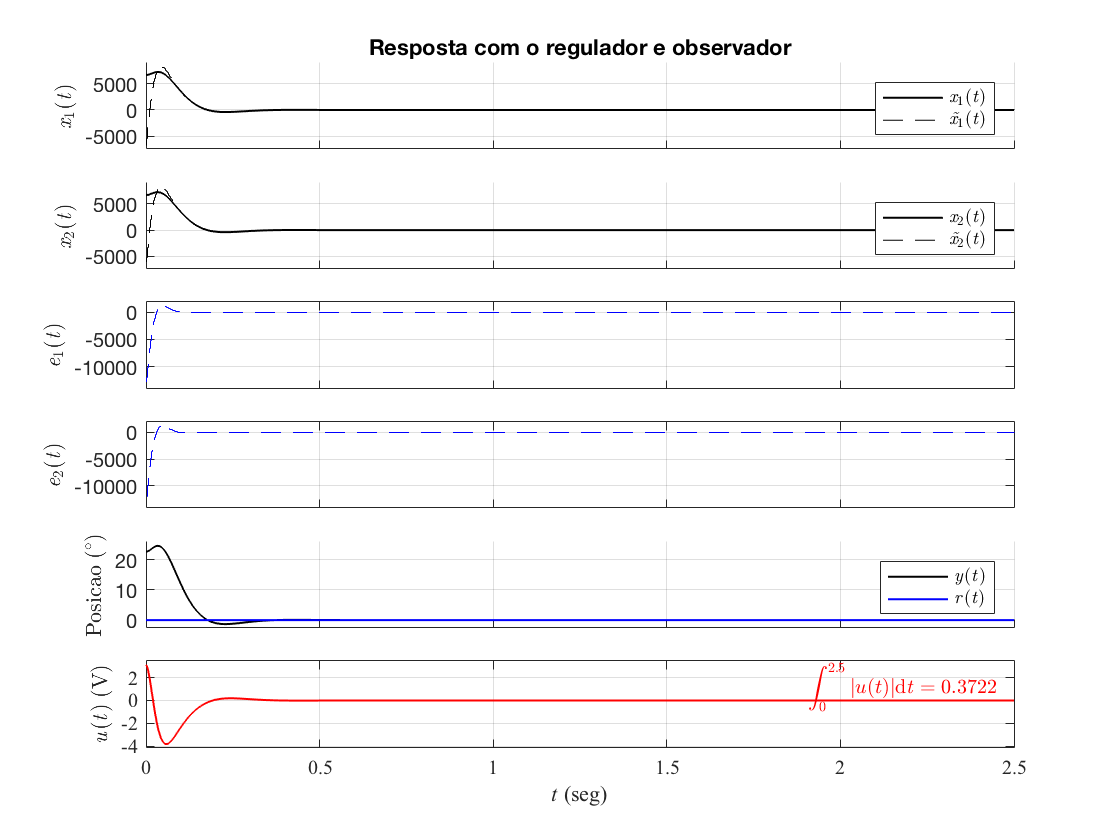

[Xor,Yor,Uor,hor] = resposta(sysdo_regl,x0or,tfinal,ur,COM_OBSERVADOR);
title(hor.Children(end),'Resposta com o regulador e observador')

*4.4.2. SERVOSSISTEMA DO TIPO 1*

Estado inicial (definido aqui como [x_real; x_estimado])

x0oc = [zeros(n,1); -6000*ones(n,1)]

x0oc =            0
           0
       -6000
       -6000


Analiza as respostas do sistema com servossistema do tipo 1

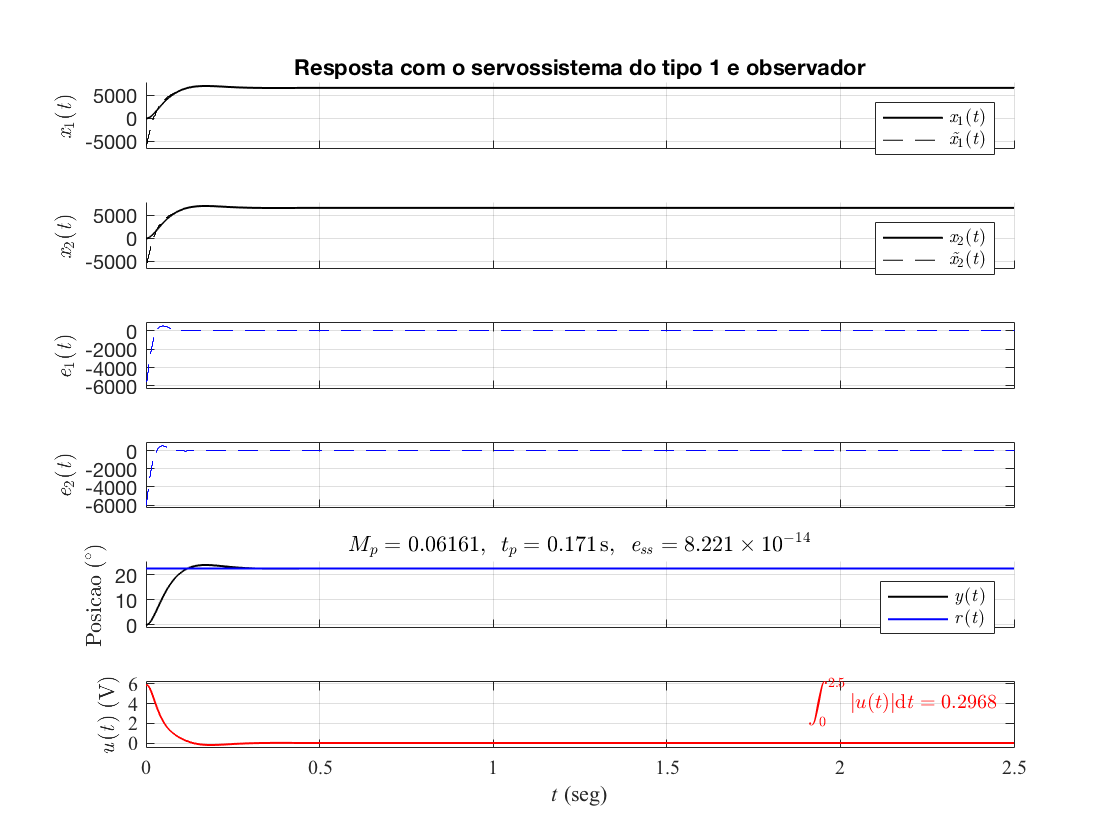

[Xoc,Yoc,Uoc,Roc,hoc] = resposta(sysdo_ctrl,x0oc,tfinal,uc,R,COM_OBSERVADOR);
title(hoc.Children(end),'Resposta com o servossistema do tipo 1 e observador')

*4.4.3. SERVOSSISTEMA COM INTEGRADOR*

Estado inicial (definido aqui como [x_real; x_estimado; integrador])

x0oi = [zeros(n,1); -6000*ones(n,1); 0]

x0oi =            0
           0
       -6000
       -6000
           0


Analiza as respostas do servossistema com integrador

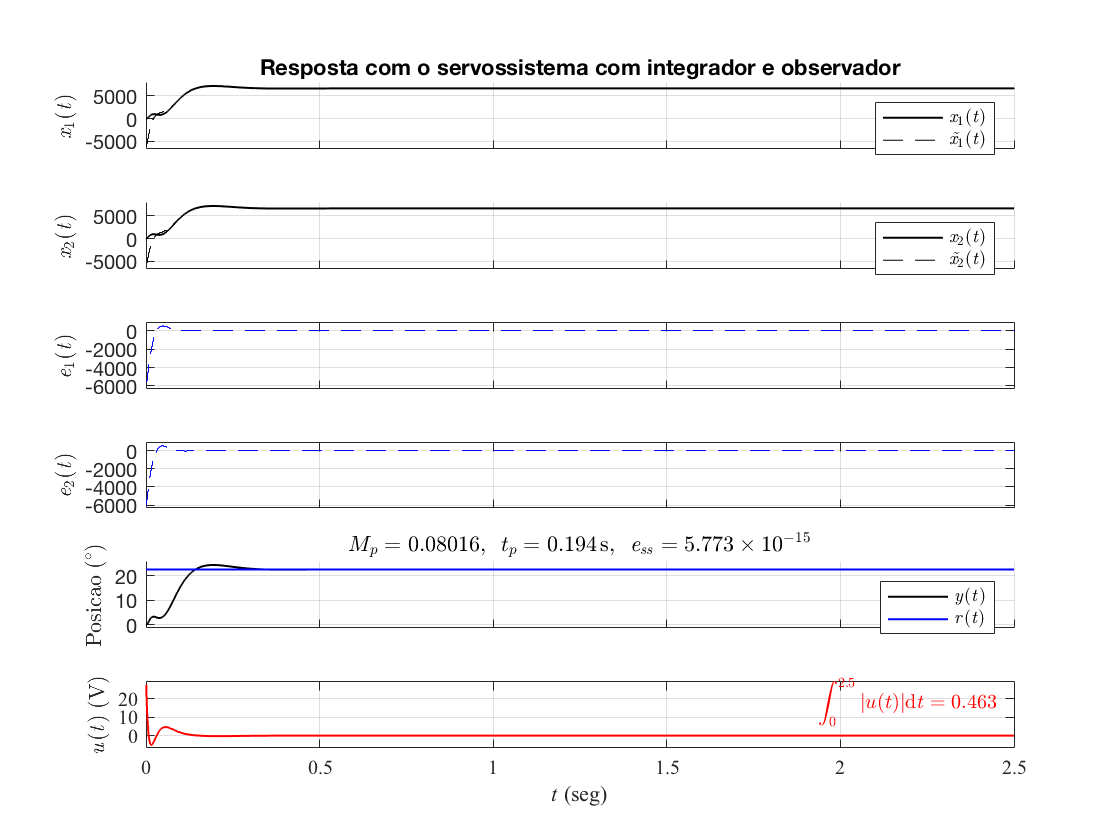

[Xoic,Yoic,Uoic,Roic,hoic] = resposta(sysdoi_ctrl,x0oi,tfinal,uic,R,COM_OBSERVADOR);
title(hoic.Children(end),'Resposta com o servossistema com integrador e observador')

*4.4.4. DEADBEAT*

Estado inicial (definido aqui como [x_real; x_estimado])

x0ob = R*ones(n,1)/sysdb_ctrl.C(1)/2;
x0ob = [eye(n), zeros(n); zeros(n), -eye(n)] * repmat(x0ob,n,1)

x0ob =    1.0e+03 *

    6.6924
    6.6924
   -6.6924
   -6.6924


Analiza as respostas do sistema com controlador deadbeat

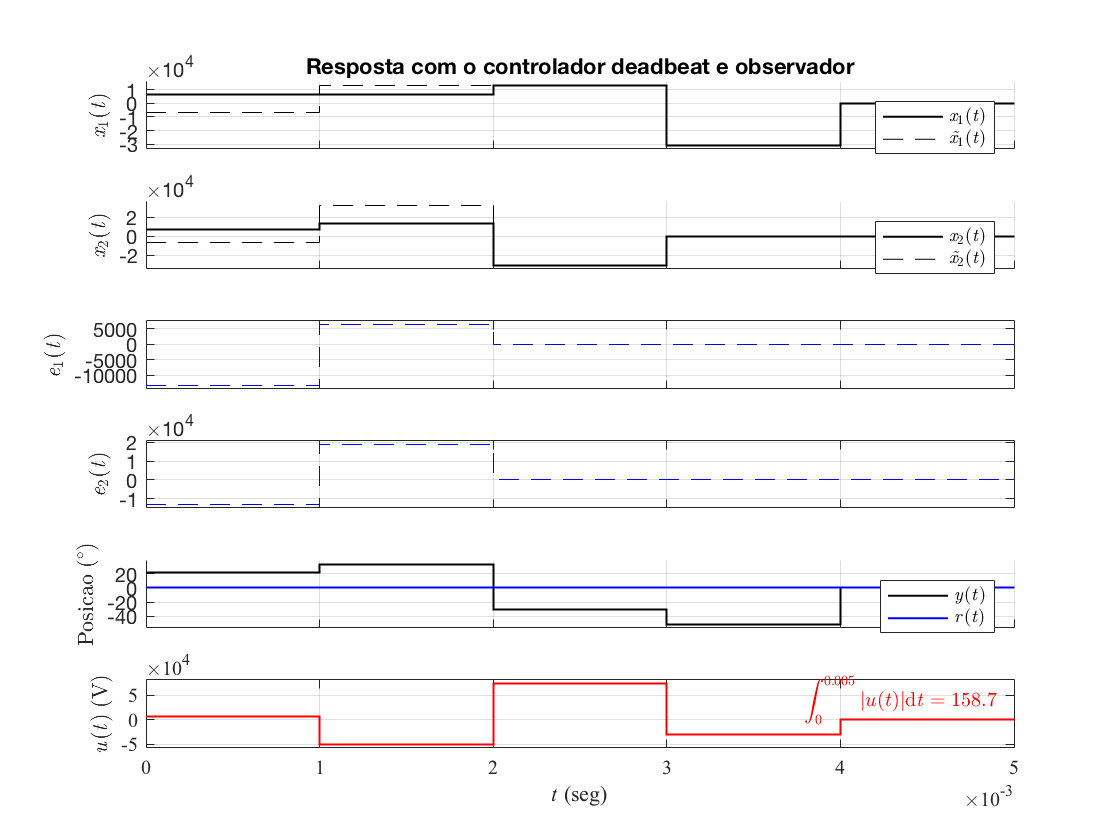

[Xobc,Yobc,Uobc,hobc] = resposta(sysdob_ctrl,x0ob,5*Ts,ubc,COM_OBSERVADOR);
title(hobc.Children(end),'Resposta com o controlador deadbeat e observador')

## **4.5. RESPOSTAS NO SIMULINK**

Respostas no Simulink consideram um sinal de entrada oscilatório e uma planta (figura abaixo) com a dinâmica do motor seguida do modelo do atuador, que pode saturar para sinais de controle elevados.

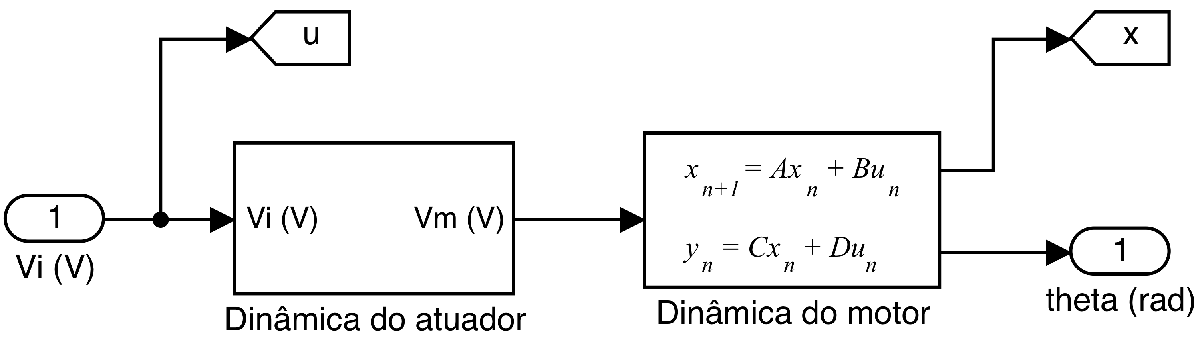

A dinâmica do motor é descrita em um espaço de estados discreto com as devidas matrizes, como ilustrado abaixo.

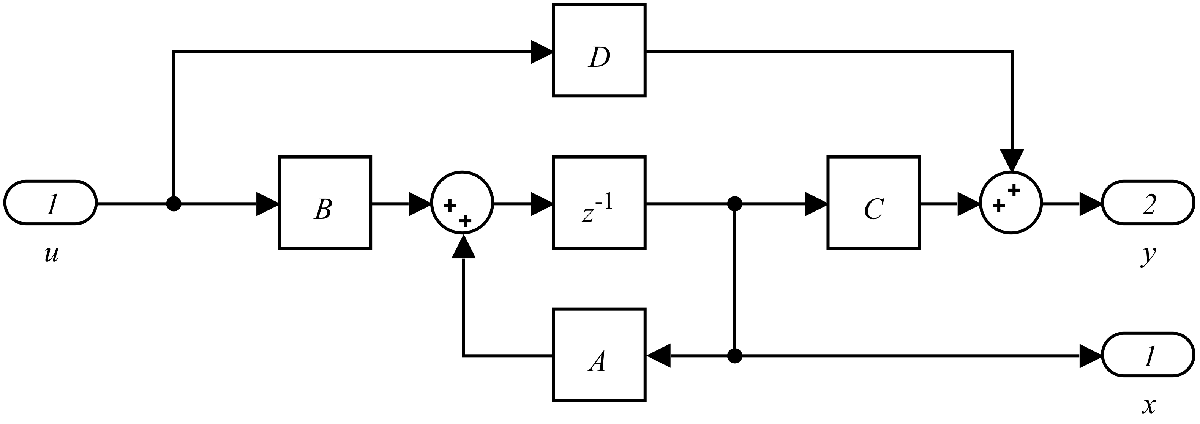

Todos os modelos de controle desenvolvidos utilizam um observador com a seguinte dinâmica para simular a resposta esperada do motor real onde apenas um tacômetro fornece informação sobre a saída do sistema modelado.

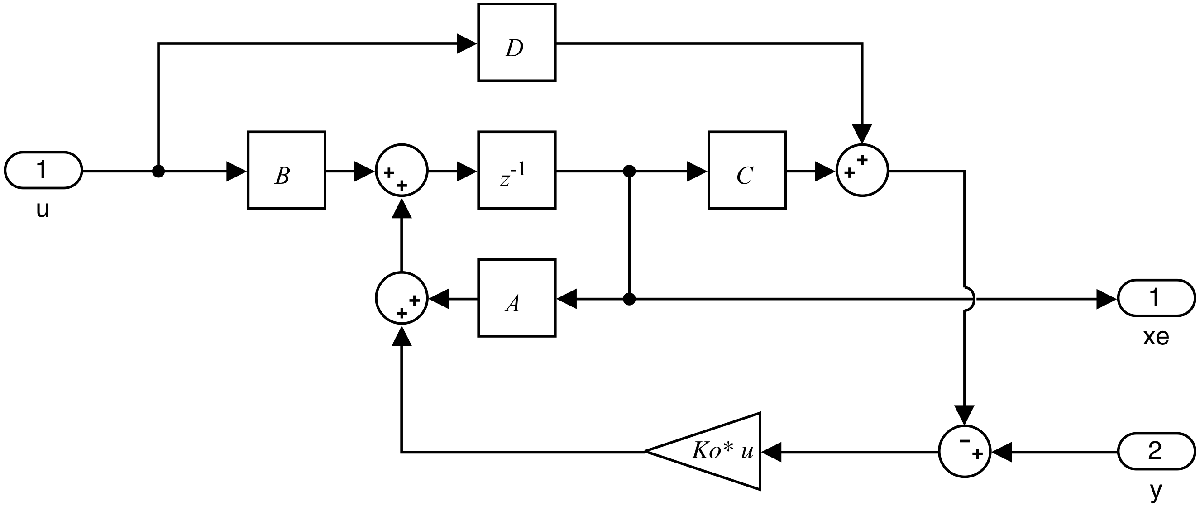

Salva os dados para carregamento no Simulink

save dados

*4.4.1. REGULADOR*

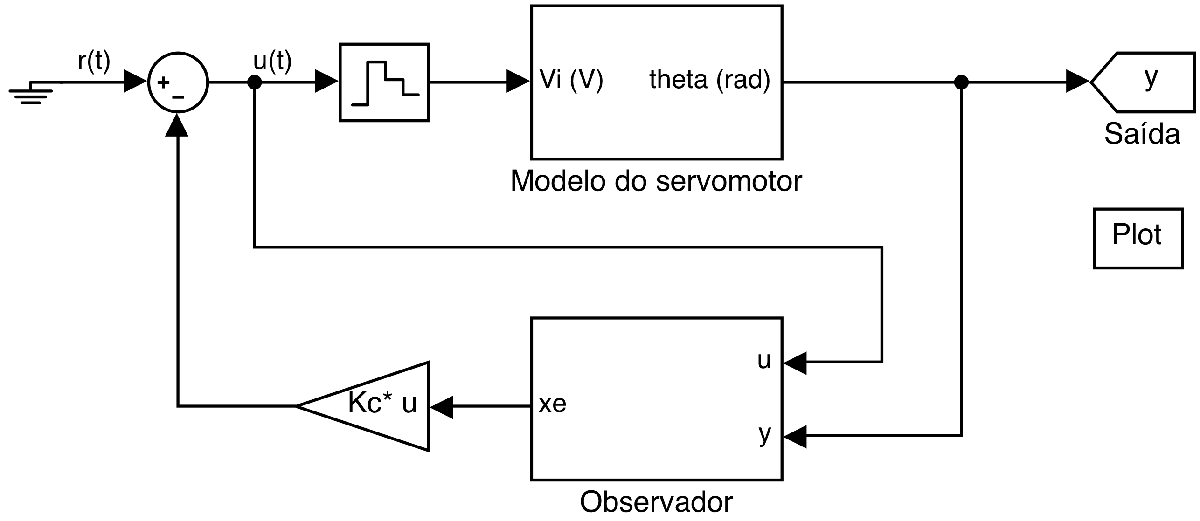

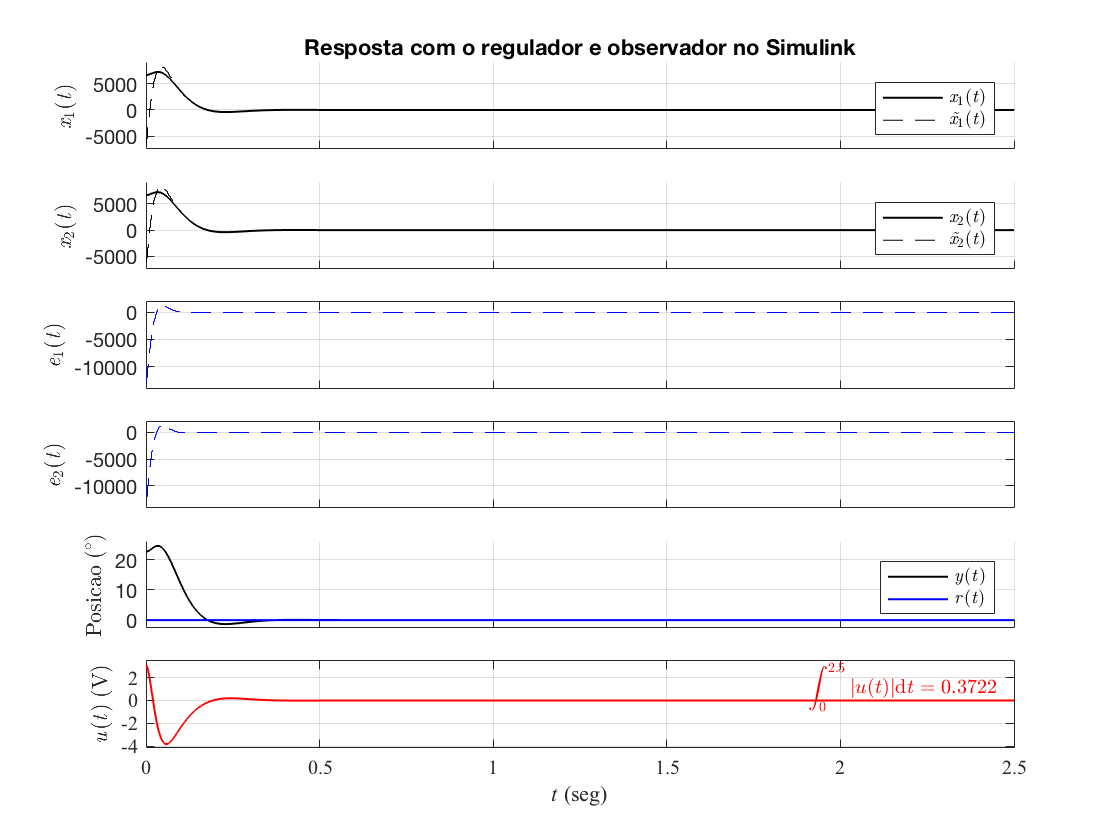

[Xor2,Yor2,Uor2,Ror2,hor2] = resposta('simulação/s_srv02_pos_d_1_regulador');
title(hor2.Children(end),'Resposta com o regulador e observador no Simulink')

*4.4.2. SERVOSSISTEMA DO TIPO 1*

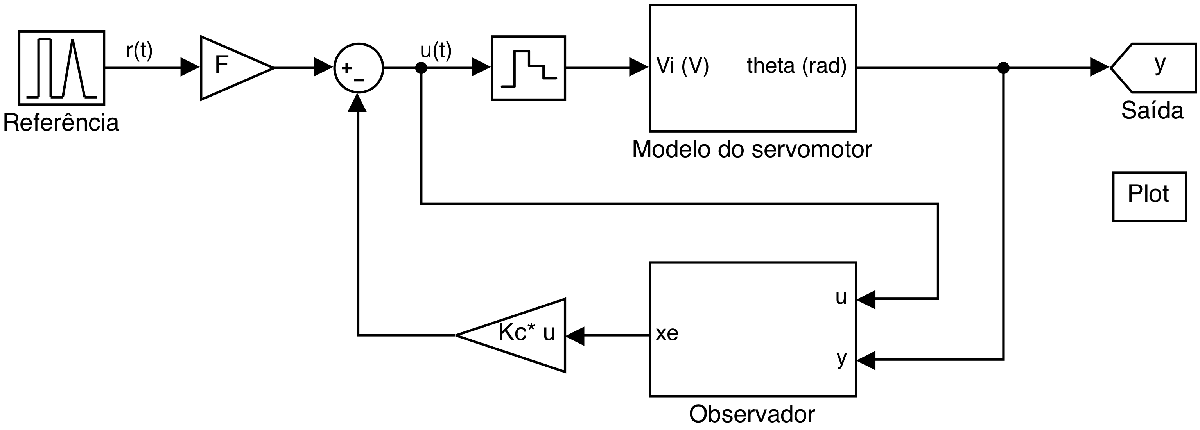

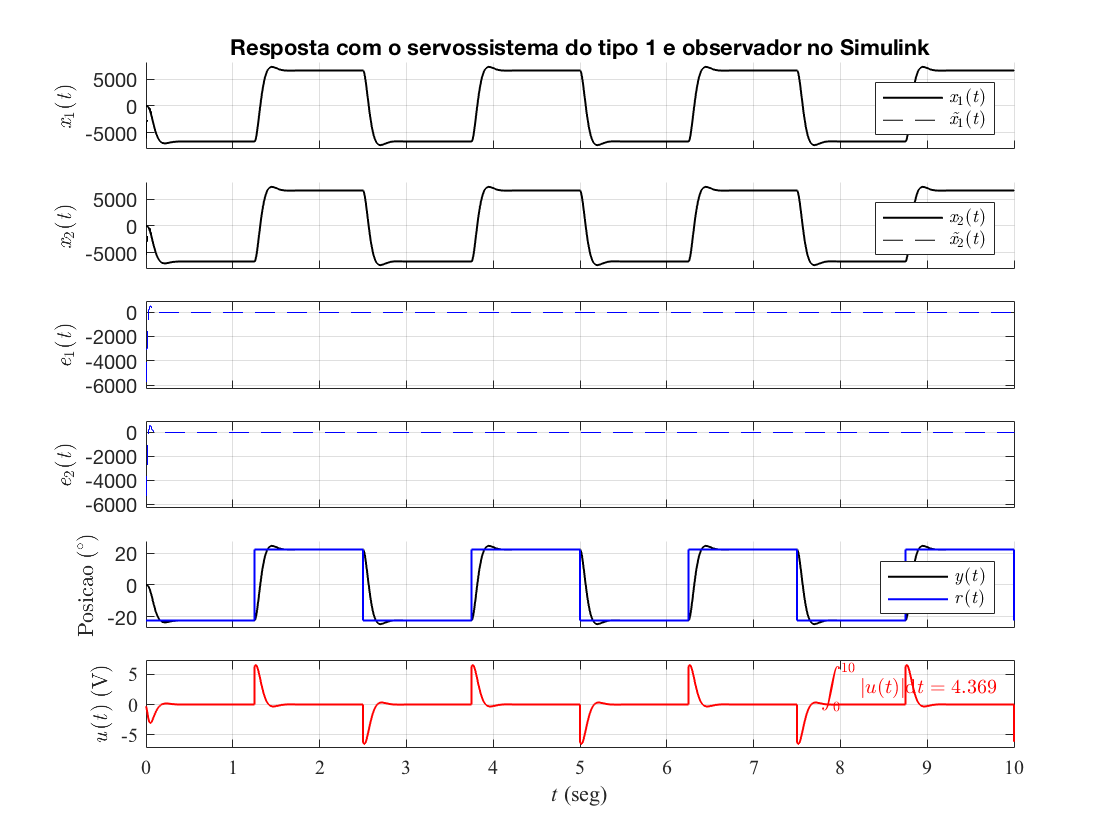

[Xoc2,Yoc2,Uoc2,Roc2,hoc2] = resposta('simulação/s_srv02_pos_d_2_servo');
title(hoc2.Children(end),'Resposta com o servossistema do tipo 1 e observador no Simulink')

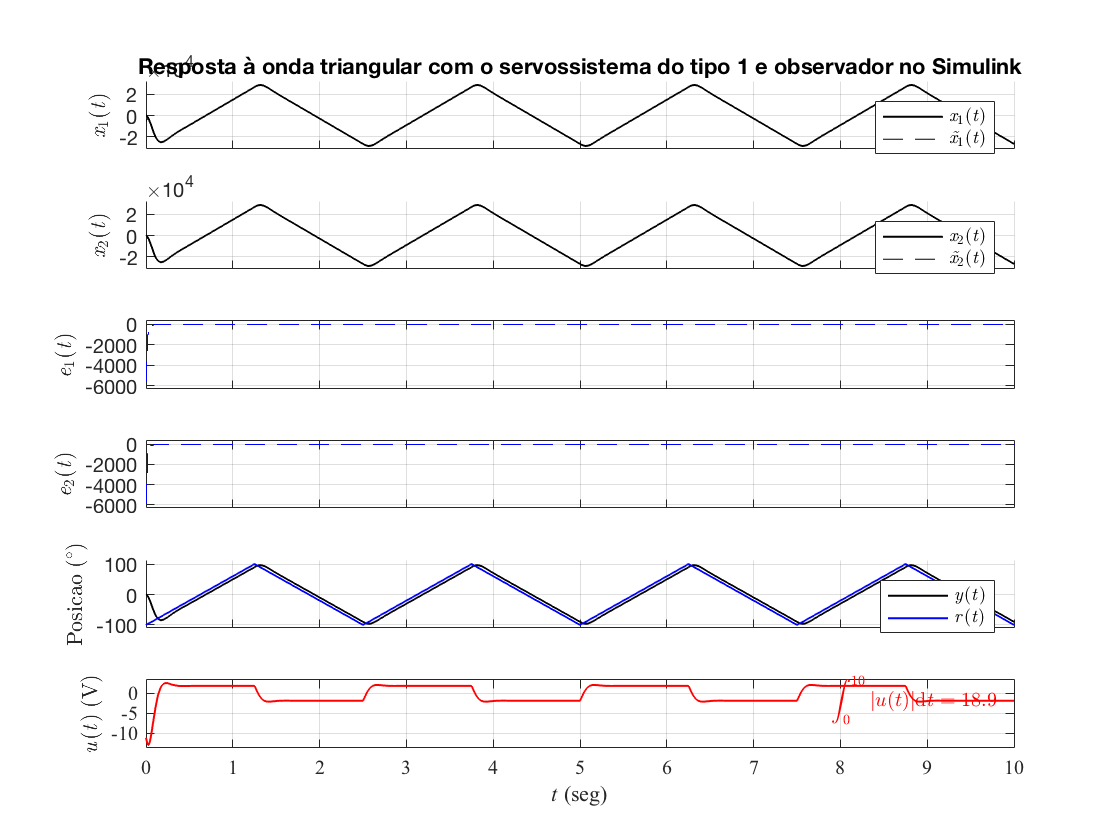

[Xoc2t,Yoc2t,Uoc2t,Roc2t,hoc2t] = resposta('simulação/s_srv02_pos_d_2_servo_triangular');
title(hoc2t.Children(end),'Resposta à onda triangular com o servossistema do tipo 1 e observador no Simulink')

*4.4.3. SERVOSSISTEMA COM INTEGRADOR*

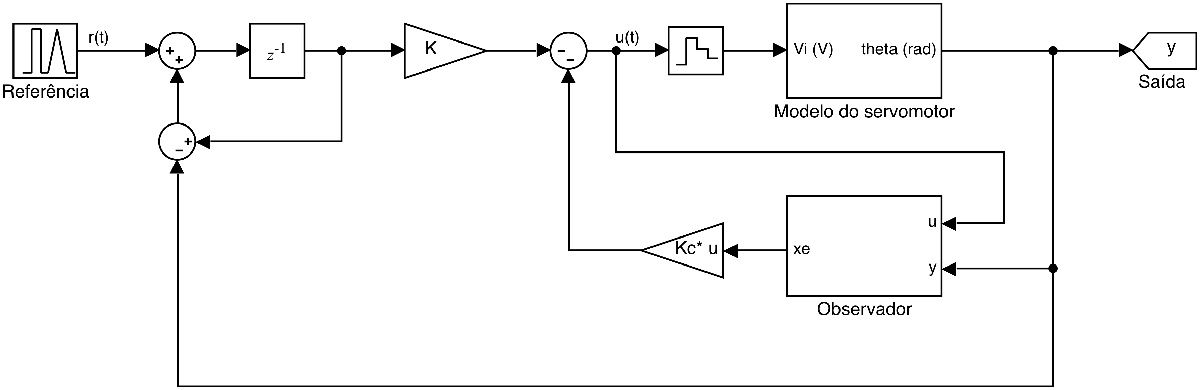

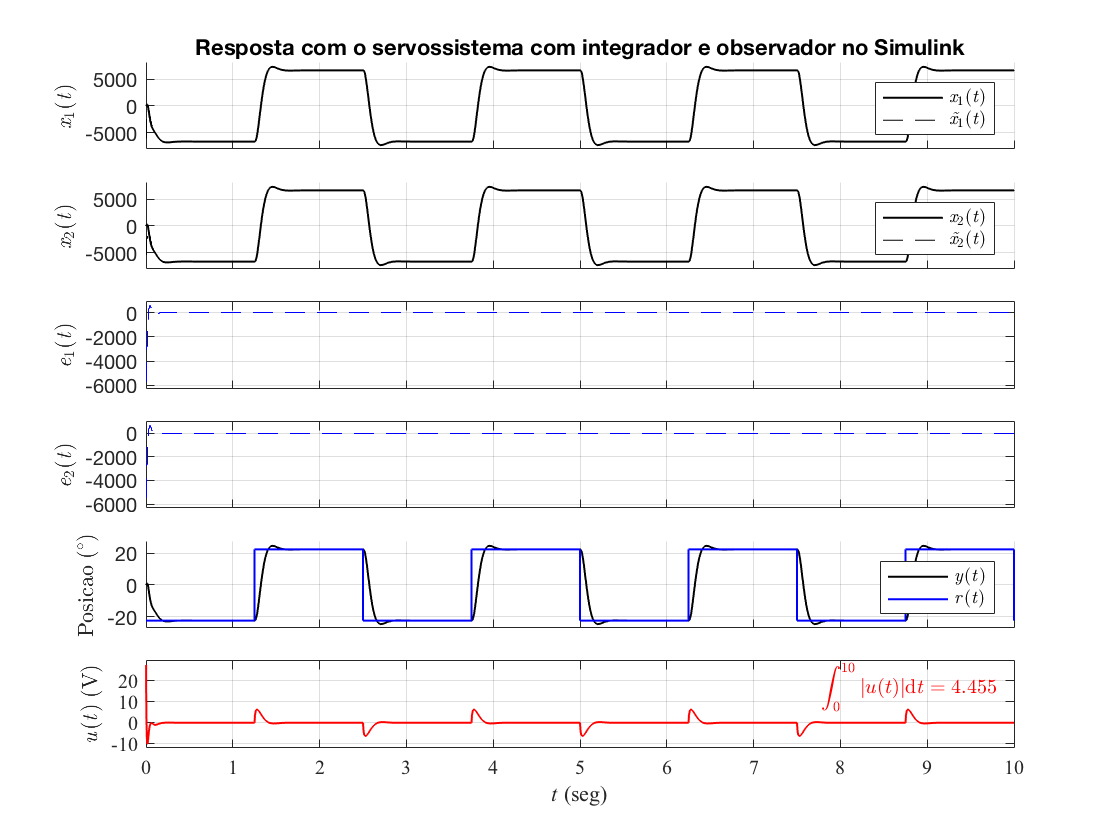

[Xoic2,Yoic2,Uoic2,Roic2,hoic2] = resposta('simulação/s_srv02_pos_d_3_integrador');
title(hoic2.Children(end),'Resposta com o servossistema com integrador e observador no Simulink')

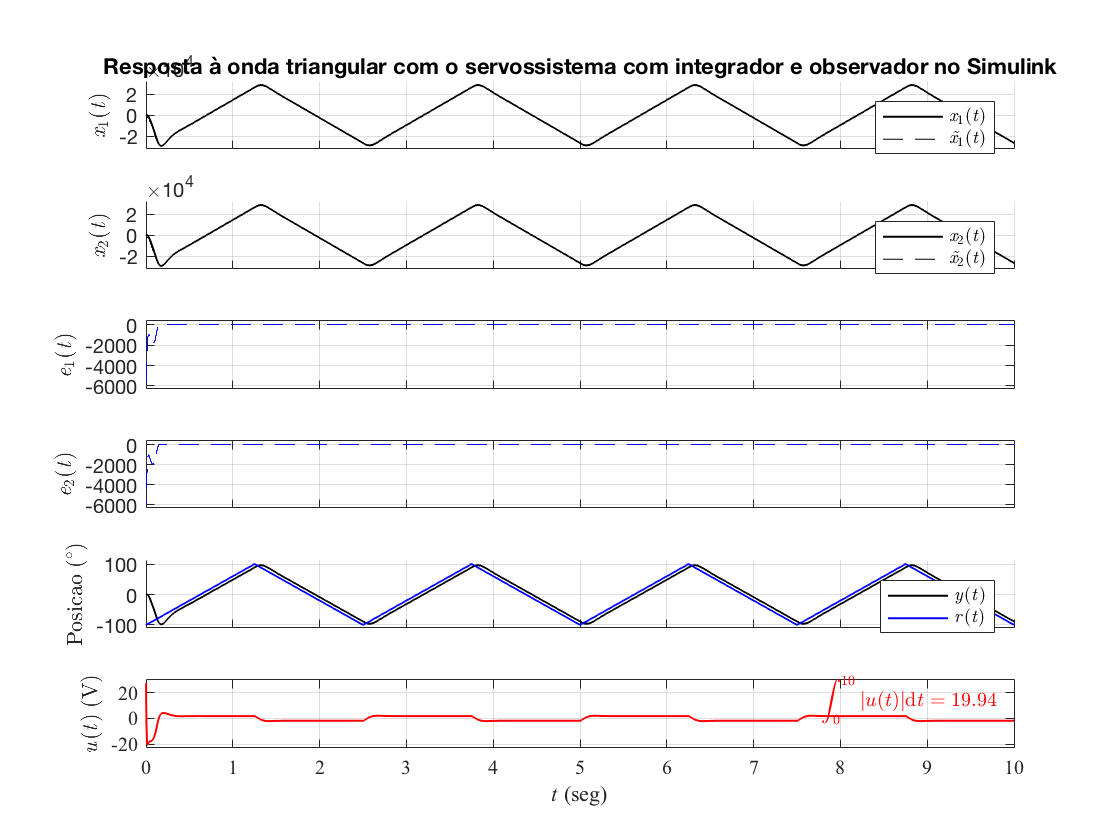

[Xoic2t,Yoic2t,Uoic2t,Roic2t,hoic2t] = resposta('simulação/s_srv02_pos_d_3_integrador_triangular');
title(hoic2t.Children(end),'Resposta à onda triangular com o servossistema com integrador e observador no Simulink')

*4.4.4. DEADBEAT*

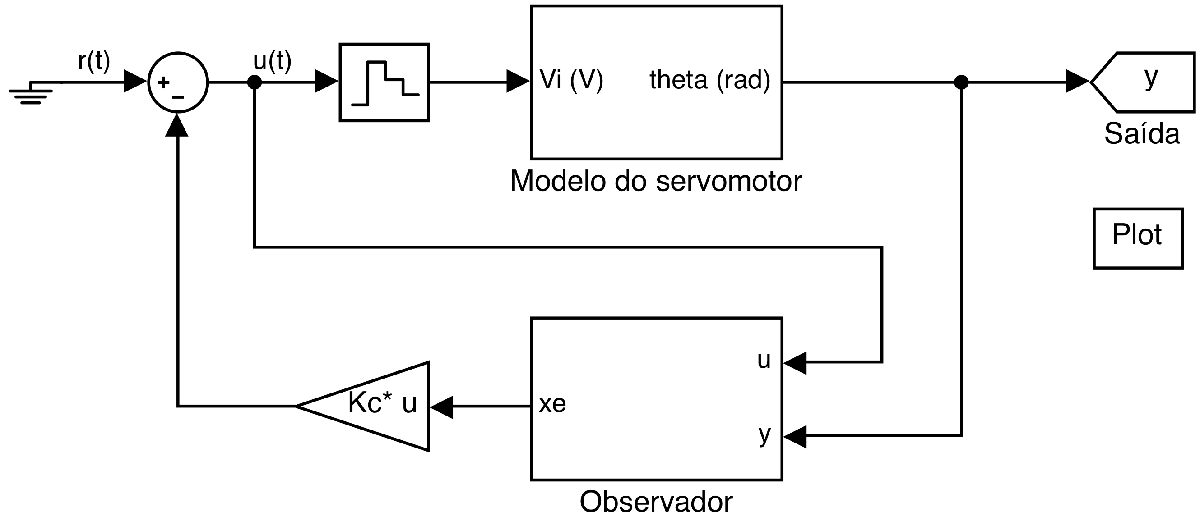

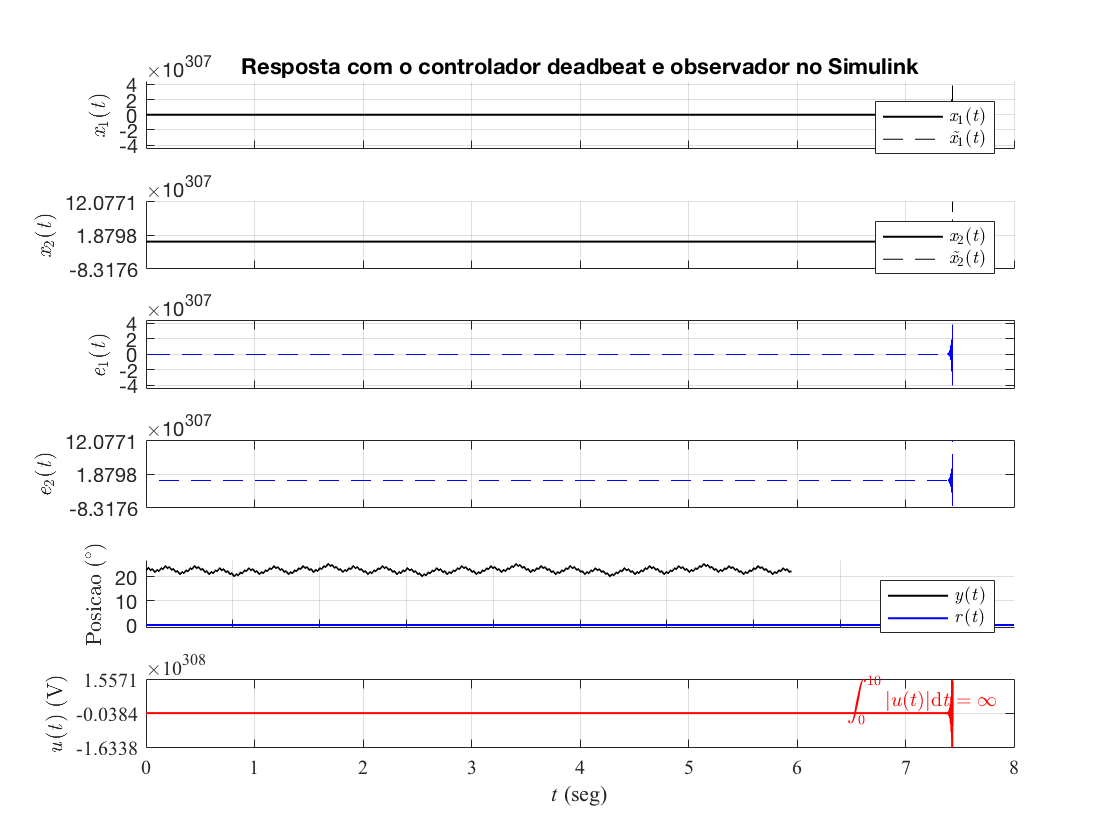

[Xobc2,Yobc2,Uobc2,Robc2,hobc2] = resposta('simulação/s_srv02_pos_d_4_deadbeat');
title(hobc2.Children(end),'Resposta com o controlador deadbeat e observador no Simulink')

# _______________________________________________________________

# FUNÇÕES INTERNAS

## VAL

Retorna o valor de uma variável simbólica com unidade

*Sintaxe:*   y` = val(x)`

*Entrada:  x*  Variável simbólica com unidade

*Saída:*     *y*  Valor `double` da variável simbólica

function y = val(x)
    y = double(separateUnits(x));
end

## UNITS

Retorna as unidades de uma variável simbólica com unidade

*Sintaxe:*   u` = units(x)`

*Entrada:  x*  Variável simbólica com unidade

*Saída:*     *u*  Unidades `string` da variável simbólica

function u = units(x)
    u = char(x);
    u = replace(u,'symunit','');
    u = replace(u,'(','');
    u = replace(u,')','');
    u = replace(u,'''','');
end

## DISPSYM

Exibe uma variável simbólica de nome `name` igual a um valor `x`

*Sintaxe:*   `dispsym(name,x,precision)`

*Entrada:  *`name        `Nome da variável simbólica a ser exibido

                `x`           Valor da variável simbólica a ser exibido

                `precision`   Valor da precisão numérica utilizada na exibição

function dispsym(name,x,precision)
    disp(vpa(sym([name ' == ' char(sym(val(x)))]),precision))
end

## SYM2TF

Converte uma Função de Transferência Simbólica para uma Função de Transferência Numérica

*Sintaxe:*    `G = sym2tf(g)`

*Entrada:   *`g`  Função de Transferência Simbólica

*Saída:*      `G`  Função de Transferência Numérica

function G = sym2tf(g)
    g = separateUnits(g);
    [n,m] = size(g);
    G = tf(zeros(n,m));
    for i = 1:n
        for j = 1:m
            [num,den] = numden(g(i,j));
            num_n = sym2poly(num);
            den_n = sym2poly(den);
            num_n = num_n/den_n(1);
            den_n = den_n/den_n(1);
            G(i,j) = tf(num_n,den_n);
        end
    end
%     G = zpk(G);
end

## TF2SYM

Converte uma Função de Transferência Numérica para uma Função de Transferência Simbólica Numérica

*Sintaxe:*   `g = tf2sym(G,var)`

*Entrada:  *`G`  Função de Transferência Numérica

                `var`  (*opcional*) Variável simbólica da frequência complexa

*Saída:*      `g`  Função de Transferência Simbólica

function g = tf2sym(G,var,precision)
    if nargin < 2
        var = vpasym('s');
    elseif ischar(var)
        var = vpasym(var);
    end
    if nargin < 3
        precision = [];
    end
    [n,m] = size(G);
    g = vpasym(zeros(n,m));
    for i = 1:n
        for j = 1:m
            [z,p,k] = zpkdata(G(i,j));
            z = z{:};
            p = p{:};
            num = 1;
            for r = 1:length(z)
                num = num * (var - z(r));
            end
            den = 1;
            for r = 1:length(p)
                den = den * (var - p(r));
            end
            f = collect(k*num/den,k);
            g(i,j) = vpasym(f,'precision',precision);
        end
    end
end

## TF2SS2

Retorna as matrizes `A`, `B`, `C` e `D` na forma canônica controlável do espaço de estados da função de transferência com numerador e denominador de coeficientes respetivos `b` e `a`, ou de expressão simbólica `g` ou de expressão numérica `sys`

*Sintaxe:*    `[A,B,C,D] = tf2ss2(b,a)`

`        [A,B,C,D] = tf2ss2(g)`

`        [A,B,C,D] = tf2ss2(sys)`

*Entrada:    *`b   `Numerador da função de transferência

`        a   `Denominador da função de transferência

`        g   `Função de Transferência Simbólica

`        sys `Função de Transferência Numérica

*Saída:       *`A   `Matriz de transição de estados

`        B   `Matriz de entrada

`        C   `Matriz de saída

`        D   `Matriz de transição direta

function [A,B,C,D] = tf2ss2(varargin)
    if nargin == 1
        sys = varargin{1};
        try
            [b,a] = tfdata(sys);
            b = b{:};
            a = a{:};
        catch ME
            if isa(sys,'sym')
                [b,a] = numden(sys);
                b = coeffs(b,'All');
                a = coeffs(a,'All');
            else
                throw(ME)
            end
        end
    else % nargin == 2
        b = varargin{1};
        a = varargin{2};
    end
    n = length(a)-1;                % Ordem do sistema
    b = fliplr(b);                  % Inverte a contagem dos coeficientes
    a = fliplr(a);                  % Inverte a contagem dos coeficientes
    b = b/a(n+1);                   % Força a(n+1) = 1
    a = a/a(n+1);                   % Força a(n+1) = 1
    
    % Matrizes
    A = [zeros(n-1,1)  eye(n-1)
                        -a(1:n)];   % Matriz de transição de estados
    B = [zeros(n-1,1)
                    1];             % Matriz de entrada
    C = b(1:n) - a(1:n)*b(n+1);     % Matriz de saída
    D = b(n+1);                     % Matriz de transição direta
end

## SSEQDISP

Exibe as equações do espaço de estados para os nomes das matrizes e da variável de entrada

*Sintaxe:*    `sseqdisp`

`        sseqdisp(arg)`

`        sseqdisp(arg,A,Aname)`

`        sseqdisp(arg,A,Aname,B,Bname)`

`        sseqdisp(arg,A,Aname,B,Bname,C,Cname)`

`        sseqdisp(arg,A,Aname,B,Bname,C,Cname,D,Dname)`

`        sseqdisp(arg,A,Aname,B,Bname,C,Cname,D,Dname,uname)`

*Entrada:    *`arg        `Nome do argumento temporal (`'t'` contínuo [padrão]; `'k'` discreto)

`        A          M`atriz de transição de estados

`        Aname      `Nome da matriz de transição de estados (string)

`        B          M`atriz de entrada

`        Bname      `Nome da matriz de entrada (string)

`        C          M`atriz de saída

`        Cname      `Nome da matriz de saída (string)

`        D          M`atriz de transição direta

`        Dname      `Nome da `m`atriz de transição direta (string)

`        uname      `Nome da variável de entrada (string)

                `precision   `Valor da precisão numérica utilizada na exibição

function sseqdisp(arg,A,Aname,B,Bname,C,Cname,D,Dname,uname,precision)
    if nargin < 1
        arg = 't';
    end
    if nargin < 2
        Aname = 'A';
    elseif ~any(any(A))
        Aname = '0';
    end
    if nargin < 4
        Bname = 'B';
    elseif ~any(B)
        Bname = '0';
    end
    if nargin < 6
        Cname = 'C';
    elseif ~any(any(C))
        Cname = '0';
    end
    if nargin < 8
        Dname = 'D';
    elseif ~any(D)
        Dname = '0';
    end
    if nargin < 10
        uname = 'u';
    end
    A_ = sym(Aname);
    B_ = sym(Bname);
    C_ = sym(Cname);
    D_ = sym(Dname);
%     u_ = str2sym([uname '(' arg ')']);
    eval(['syms ' uname '(t)'])
    syms x(t) y(t)
    switch lower(arg)
        case 't'
            eval(['disp(diff(x) == collect(A_*x + B_*' uname ',x))'])
            eval(['disp( y == collect(C_*x + D_*' uname ',x))'])
        case 'k'
            eval(['disp(x([arg ''+1'']) == collect(A_*x(arg) + B_*' uname '(arg),x(arg)))'])
            eval(['disp(y([arg ''+1'']) == collect(C_*x(arg) + D_*' uname '(arg),x(arg)))'])
    end
    if any(any(A)), disp(vpa(sym([Aname '==' char(sym(A))]),precision)), end
    if any(any(B)), disp(vpa(sym([Bname '==' char(sym(B))]),precision)), end
    if any(any(C)), disp(vpa(sym([Cname '==' char(sym(C))]),precision)), end
    if any(any(D)), disp(vpa(sym([Dname '==' char(sym(D))]),precision)), end
end

## CTRB2

Retorna a matriz de controlabilidade de Kalman `Co` com base nas matrizes `A` e `B` do espaço de estado

*Sintaxe:*    `Co = ctrb2(A,B)`

*Entrada:    *`A   `Matriz de transição de estados

`        B   `Matriz de entrada

*Saída:       *`Co  `Matriz de controlabilidade de Kalman

function Co = ctrb2(A,B)
    n = length(A);            % Ordem do sistema
    Co = sym(zeros(n));
    for i = 1:n
        Co(:,i) = A^(i-1)*B;  % Calcula a i-ézima coluna de Co
    end
    try                       % Se Co não contiver simbólicas
        Co = double(Co);      % ... converte em númerico
    catch
    end
end

## ISCTRB

Verifica se o sistema é controlável com base na matriz de controlabilidade `Co`

*Sintaxe:*    `TF = isctrb(Co)`

*Entrada:    *`Co  `Matriz de controlabilidade de Kalman

*Saída:       *`TF  `Verdadeiro ou falso indicando se o sistema é controlável

function TF = isctrb(Co)
    n = length(Co);  % Ordem do sistema
    m = rank(Co);    % Calcula o posto de Co
    TF = m == n;     % Verifica se o posto é igual à ordem do sistema
end

## OBSV2

Retorna a matriz de observabilidade de Kalman `Ob` com base nas matrizes `A` e `C` do espaço de estado

*Sintaxe:*    Ob` = obsv2(A,C)`

*Entrada:    *`A   `Matriz de transição de estados

`        C   `Matriz de saída

*Saída:       *`Ob  `Matriz de observabilidade de Kalman

function Ob = obsv2(A,C)
    n = length(A);            % Ordem do sistema
    Ob = sym(zeros(n));
    for i = 1:n
        Ob(i,:) = C*A^(i-1);  % Calcula a i-ézima coluna de Ob
    end
    try                       % Se Ob não contiver simbólicas
        Ob = double(Ob);      % ... converte em número
    catch
    end
end

## ISOBSV

Verifica se o sistema é completamente observável e retorna seu grau de observabilidade com base na matriz de observabilidade `Ob`

*Sintaxe:*    `[TF,m] = isobsv(Co)`

*Entrada:    *`Ob  `Matriz de observabilidade de Kalman

*Saída:       *`TF  `Verdadeiro ou falso indicando se o sistema é completamente observável

`        m   `Grau de observabilidade do sistema indicando quantas variávels são observáveis

function [TF,m] = isobsv(Ob)
    n = length(Ob);      % Ordem do sistema
%     m = rank(Ob);        % Calcula o posto de Ob
    idx = obsvvars(Ob);  % Determina quais...
    m = size(idx,1);     % (...) e quantas variáveis são observáveis
    TF = m == n;         % Verifica se é igual à ordem do sistema
end

## OBSVVARS

Retorna o índice das variáveis em que o sistema é observável com base na matriz de observabilidade `Ob`

*Sintaxe:*    `idx = obsvvars(Ob)`

*Entrada:    *`Ob   `Matriz de observabilidade de Kalman

*Saída:       *`idx  `Índice das variáveis em que o sistema é observável 

function idx = obsvvars(Ob)
    [~,idx] = ld(Ob);  % Determina as linhas linearmente dependentes
end

## LD

Retorna as linhas `Ar` da matriz `A` que são linearmente dependentes das outras linhas, ordenadas de forma que `abs(diag(R))` é decrescente, onde `R` é a matriz triangular superior da decomposição ortogonal-triangular de `A`

*Sintaxe:*    `[Ar,idx] = ld(A)`

*Entrada:    *`A    `Matriz numérica de entrada

*Saída:       *`Ar   `Linhas das variáveis linearmente dependetes

`        idx  `Índice das variáveis linearmente dependetes

function [Ar,idx] = ld(A)
    [~,~,e] = qr(A,0);        % Calcula a decomposicão ortogonal-triangular
    r = rank(A);              % Calcula o posto
    idx = sort(e(r+1:end));   % Escolhe os índices das linhas nulas ...
                              % (...) da matriz triangular superior
    Ar = A(idx,:);            % Seleciona as linhas com base nesses índices ...
                              % (...) que são ordenadas de forma que ...
                              % (...) abs(diag(R)) é decrescente
end

## SECORDPARAM

Retorna os parâmetros de segunda ordem: coeficiente de amortecimento `zeta` e frequência natural não amortecida `wn`; com base em um tempo de pico `tp` e máximo sobressinal Mp

*Sintaxe:*    `[zeta,wn] = secordparam(tp,Mp)`

*Entrada:    *`tp  `Tempo de pico (s)

`        Mp  `Máximo sobressinal

*Saída:       *`zeta   `Coeficiente de amortecimento

`        wn     `Frequência natural não amortecida (rad/s)

function [zeta,wn] = secordparam(tp,Mp,precision)
    % Variáveis auxiliares
    u = vpasymunit('precision',precision);
    l = abs(log(Mp));
    x = sqrt(pi^2 + l^2);
    
    % Saída
    zeta = l / x;            % Coeficiente de amortecimento
    wn   = x / tp  * u.rad;  % Frequência natural não amortercida
end

## SECORD2POLES

Retorna os coeficientes `pc` e os polos `r` do polinômio característico de um sistema de segunda ordem com coeficiente de amortecimento `zeta` e frequência natural não amortecida `wn`

*Sintaxe:*    `[pc,p] = secord2poles(z,wn)`

*Entrada:    *`zeta   `Coeficiente de amortecimento

`        wn     `Frequência natural não amortecida (rad/s)

*Saída:       *`pc     `Coeficientes do polinômio característico

`        p      `Polos do polinômio característico

`        sigma  `Inverso da constante de tempo (rad/s)

`        wn     `Frequência natural não amortecida (rad/s)

function [pc,p,sigma,wd] = secord2poles(zeta,wn)
    sigma = zeta*wn;                          % Inverso da constante de tempo (rad/s)
    wd    = wn.*sqrt(1-zeta^2);               % Frequência natural amortecia (rad/s)
    p     = -val(sigma) + [1,-1]*1i*val(wd);  % Polos
    pc    = poly(val(p));                     % Coeficientes
end

## C2DPOLES

Transforma os coeficientes os polos `p` do polinômio característico de um sistema contínuo nos coeficientes `zpc` e nos polos `zp` do polinômio característico  no plano discreto equivalente para um período de amostragem `Ts`

*Sintaxe:*    `[zpc,zp] = c2dpoles(p,Ts)`

*Entrada:    *`p      `Polos contínuos do polinômio característico

`        Ts     `Período de amostragem

*Saída:       *`zpc    `Coeficientes do polinômio característico no plano discreto

`        zp     `Polos discretos do polinômio característico

function [zpc,zp] = c2dpoles(p,Ts)
    zp  = exp(val(Ts)*p);  % Polos
    zpc = poly(zp);        % Coeficientes
end

## ACKER2

Retorna o vetor de ganhos `K` da lei de controle por realimentação de estados ou saída com base nas matrizes `A` e `E` (igual a B ou `C`) do espaço de estados e no polos desejados `p` a serem alocados utilizando a fórmula de Ackermann

*Sintaxe:*    `K = acker2(A,E,p)`

*Entrada:    *`A   `Matriz de transição de estados

`        E   `Matriz de entrada (`B` para controlador de estados) ou de saída (`C` para observador de estados)

`        p   `Polos desejados

*Saída:       *`K   `Vetor de ganhos do controlador ou observador de estados

function K = acker2(A,E,p)
    n     = length(A);                   % Ordem do sistema
    pc    = poly(p);                     % Coeficientes do polinômio característico
    Phi_A = polyvalm(pc,A);              % Avalia o polinômio característico em A
    if size(E,1) == size(A,1)
        % B, controlador de estados
        Co = ctrb2(A,E);                 % Matriz de controlabilidade
        K  = [zeros(1,n-1) 1]/Co*Phi_A;  % Vetor de ganhos
    elseif size(E,2) == size(A,2)
        % C, observador de estados
        Ob = obsv2(A,E);                 % Matriz de observabilidade
        K  = Phi_A/Ob*[zeros(n-1,1);1];  % Matriz de ganhos
    else
        error('A matriz E deve ter o menos número de linhas ou de colunas da matriz A')
    end
end

## REDSS

Retorna as matrizes `Ac`, `Bc`, `Cc` e `Dc` do espaço de estados reduzido para um espaço de estados original com matrizes `A`, `B`, `C` e `D` de um regulador (`type = -1`), um servossistema do tipo 0 (`type = 0`) ou um servossistema do tipo 1 (`type = 1`) com realimentação de estados, vetor de ganhos `K` do controlador e `Ko` do observador, quando aplicável

*Sintaxe:*    `[Ac,Bc,Cc,Dc] = redss(A,B,C,D,K)`

`        [Ac,Bc,Cc,Dc] = redss(A,B,C,D,K,type)`

`        [Ac,Bc,Cc,Dc] = redss(A,B,C,D,K,type,Ko)`

*Entrada:    *`A         `Matriz de transição de estados

`        B         `Matriz de entrada

`        C         `Matriz de saída

`        D         `Matriz de transição direta

`        K         `Vetor de ganhos do controlador

`        type      `Tipo do controlador (-1 para regulador [padrão]; `0` para servossistema do tipo 0; `1` para servossistema do tipo 1)

`        Ko        `Vetor de ganhos do observador, quando aplicável

*Saída:       *`Ac  `Matriz de transição de estados do sistema reduzido

`        Bc  `Matriz de entrada do sistema reduzido

`        Cc  `Matriz de saída do sistema reduzido

`        Dc  `Matriz de transição direta do sistema reduzido

`        Fc  `Matriz de alimentação direta do sistema reduzido

function [Ac,Bc,Cc,Dc,Fc] = redss(A,B,C,D,K,type,Ko)
    % Verificação do sistema
    n  = length(A);              % Ordem do sistema
    I  = eye(n);                 % Matriz identidade n x n
    O  = zeros(n);               % Matriz nula n x n
    O_ = zeros(n,1);             % Vetor  nulo n x 1
    
    % Ganho de alimentação direta
    if nargin < 6 || type == -1
        % Regulador
        Fc = 0;
        type = -1;
    else
        % Servossistema
        switch type
            case 0
                % Tipo 0
                Fc = 1;
            case 1
                % Tipo 1
                Fc = inv(C/(I - (A - B*K))*B);
            otherwise
                error('Type input value must be -1, 0 or 1')
        end
    end
    
    if type == 0
        Kn = K(end);
        K  = K(1:end-1);
    end
    
    % Redução do sistema
    Ac = A - B*K;                % Acopla A
    Bc = B*Fc;                   % Reduz B
    Cc = C - D*K;                % Acopla C
    Dc = D*Fc;                   % Reduz D
    
    % Observador
    if nargin >= 7 && ~isempty(Ko)
        % Redução do sistema
        Ac = [Ac,      -B*K
               O,  A - Ko*C];    % Acopla A
           
        Bc = [Bc
              O_];               % Reduz B

        Cc = [Cc,  -D*K];        % Acopla C
    end
    
    % Integrador
    if type == 0
        % Ajusta os zeros caso haja um observador de estados
        if nargin >= 7 && ~isempty(Ko)
            O_ = [O_
                  O_];
        end
        
        % Redução do sistema
        Ac = [ Ac,   -Bc*Kn;
              -Cc,  1+Dc*Kn];    % Acopla A
          
        Bc = [O_
               1];               % Reduz B
          
        Cc = [Cc,  -Dc*Kn];      % Acopla C
        
        Dc = 0;                  % Reduz D
    end
end

## INCSS

Retorna as matrizes `Ai`, `Bi`, `Ci` e `Di` do espaço de estados aumentado para um espaço de estados original com matrizes `A`, `B`, `C` e `D` de forma a adicionar um integrador no sistema

*Sintaxe:*    `[Ai,Bi,Ci,Di,Ki] = incss(A,B,C,D,K)`

*Entrada:    *`A   `Matriz de transição de estados

`        B   `Matriz de entrada

`        C   `Matriz de saída

`        D   `Matriz de transição direta

*Saída:       *`Ai  `Matriz de transição de estados do sistema aumentado

`        Bi  `Matriz de entrada do sistema aumentado

`        Ci  `Matriz de saída do sistema aumentado

`        Di  `Matriz de transição direta do sistema aumentado

function [Ai,Bi,Ci,Di] = incss(A,B,C,D)
    n  = length(A);  % Ordem do sistema
    O = zeros(n,1);  % Vetor nulo
    % Aumenta o espaço de estados
    Ai = [ A  O
          -C  1];
    Bi = [B
          0];
    Ci = [C  0];
    Di = D;
end

## RESPOSTA

Exibe os gráficos da simulação das variáveis de estado `X`, de saída `y`, de controle `U` e de entrada `r` no tempo até `tfinal` para um estado inicial `x0` do sistema `sys` com função simbólica da lei de controle `u` por realimentação de estados com amplitude `R` de variável de entrada

*Sintaxe:*    `[X,h] = resposta(sys,x0,tfinal)`

`        [X,y,U,h] = resposta(sys,x0,tfinal,u)`

`        [X,y,U,r,h] = resposta(sys,x0,tfinal,u,R)`

`        resposta(...,has_obsv)`

*Entrada:    *`sys        `Sistema no espaço de estados

        x0         Estado inicial das `n` variáveis de estado (`n` × `1`)

`        tfinal     `Tempo final da simulação (s)

`        u          `Função simbólica da lei de controle por realimentação de estados (deve conter `r`, `x1`, `x2`, `x3`, ...)

`        R          `Amplitude da variável de entrada

`        has_obsv   True` ou `false` (padrão) se o sistema possui observador de estados

*Saída:       *`X  `Matriz das `n` variáveis de estado simuladas nos `k` tempos (`n` × `k`)

`        y  `Vetor da variável de saída simulada nos `k` tempos (`1` × `k`)

`        U  `Matriz das `n` variáveis de controle simuladas nos `k` tempos (`n` × `k`)

`        r  `Vetor da variável de entrada simulada nos `k` tempos (`1` × `k`)

`        h  `Objeto da figura exibida

function [X,varargout] = resposta(varargin)
    if nargin == 1
        model = varargin{1};
        warning('off','Simulink:blocks:MatchingGotoNotFound')
        out = sim(model,'SaveFormat','Dataset');
        
        t   = out.x1 (:,1);
        x1  = out.x1 (:,2);
        x2  = out.x2 (:,2);
        xe1 = out.xe1(:,2);
        xe2 = out.xe2(:,2);
        e1  = out.e1 (:,2);
        e2  = out.e2 (:,2);
        y   = out.y  (:,2);
        r   = out.r  (:,2);
        Vm  = out.Vm (:,2);
        u   = out.u  (:,2);
        
        t  = t';
        X1 = [x1  x2]';
        X2 = [xe1 xe2]';
        E  = [e1  e2]';
        y  = y';
        r  = r';
        Vm = Vm';
        U  = u';
        
        X = [X1; E];
        R = abs(r(end));
        W = trapz(t,abs(U));   % Energia do esforço de controle
        varargout = {y,U,r};
        
        tp = t(end);
        
        m  = size(U,1) + 1;
        dt = t(2)-t(1);
        Ts = dt;
        n  = 2*2;
        has_obsrv = true;
    else
        if islogical(varargin{end})
            has_obsrv = varargin{end};
            varargin{end} = [];
            narg = nargin-1;
        else
            has_obsrv = false;
            narg = nargin;
        end
        if narg < 3
            error('MATLAB:narginchk:notEnoughInputs')
        else
            sys    = varargin{1};
            x0     = varargin{2};
            tfinal = varargin{3};
        end
        if narg >= 4
            u = varargin{4};
        end
        if narg >= 5
            R = varargin{5};
        end
        
        % Simulação
        n  = order(sys);
        n_ = fix(n/2);
        A = sys.A;
        B = sys.B;
        C = eye(n);      % Muda a saída ...
        D = zeros(n,1);  % (...) para x(t)
        if isprop(sys,'Ts')
            dt = sys.Ts;
            sys2 = ss(A,B,C,D,dt);
        else
            dt = val(tfinal)/1e4;
            sys2 = ss(A,B,C,D);
        end
        t = 0:dt:val(tfinal);
        k = length(t);
        if narg < 5
            R = 1;
        end
        if has_obsrv
            x01 = x0(1:n_);
            x02 = x0(n_+1:2*n_);
            e0  = x02 - x01;
            z0  = x0(2*n_+1:end);
            x0  = [x01; e0; z0];
        end
        X0 = initial(sys2,x0,t)';
        if narg <= 4
            X = X0;
            if narg == 3
                m = 0;
                varargout = {};
            else
                R = 0;
                r = zeros(1,k);
                tp  = t(end);
                Mp  = [];
                ess = [];
            end
        else
            opt = stepDataOptions('StepAmplitude',R);
            X = X0 + step(sys2,t,opt)';
            r = R*ones(1,k);
        end
        if has_obsrv
            X1 = X(1:n_,:);
            E  = X(n_+1:2*n_,:);
            X2 = X1 + E;
            Z  = X(2*n_+1:end,:);
        else
            X1 = X;
            X2 = X;
            Z  = [];
        end
        if narg >= 4
            u = str2func(['@(x,r)' replace(char(u),compose('x%d',1:n),compose('x(%d,:)',1:n))]);
            U = u([X2;Z],r);
            W = trapz(t,abs(U));   % Energia do esforço de controle
            y = sys.C*X + sys.D*r;
            varargout = {y,U};
            if narg > 4
                varargout{end+1} = r;
                [ymax,ind] = max(abs(y));
                tp  = t(ind);
                Mp  = ymax/R - 1;
                ess = r(end) - y(end);
            end
            y = rad2deg(y);
            r = rad2deg(r);
            m = size(U,1) + 1;
        end
        Ts = dt;
        n = 2*n_;
    end
    
    % Gráfico
    N  = n + m;
    n_ = n/2;
    h = figure;
    for i = 1:n
        ax(i) = subplot(N,1,i);
        if ~has_obsrv
            plotit(ax(i),t,X1(i,:),'k',Ts,['$$\it x_{\rm ' num2str(i) '} ( \it t \rm )$$']);
        elseif i <= n_
            hold(ax(i),'on')
            [p(1),yl] = plotit(ax(i),t,X1(i,:),'k'  ,Ts,['$$\it x_{\rm ' num2str(i) '} ( \it t \rm )$$']);
             p(2)     = plotit(ax(i),t,X2(i,:),'k--',Ts,['$$\it x_{\rm ' num2str(i) '} ( \it t \rm )$$'],yl,0.5);
            legend(ax(i),p,{['$$\it x_{\rm '         num2str(i) '} \rm ( \it t \rm )$$']
                            ['$$\it \tilde{x}_{\rm ' num2str(i) '} \rm ( \it t \rm )$$']}, ...
                   'Location','Northeast','Interpreter','latex')
        else
            j = i-n_;
            plotit(ax(i),t,E(j,:),'b--',Ts,['$$\it e_{\rm ' num2str(j) '} ( \it t \rm )$$'],[],0.5);
        end
    end
    if m > 0
        ax(n+1) = subplot(N,1,n+1);
        hold on
        [p(1),yl] = plotit(ax(n+1),t,y,'k',Ts,'$$\rm Posicao \; (^\circ)$$');
        p(2) = plotit(ax(n+1),t,r,'b',Ts,[],yl);
        if tp ~= t(end)
            title(ax(n+1),['$$M_p = ' num2str2(Mp,4) ', \enspace t_p = ' num2str2(tp,4) '\, \rm s \it, \enspace e_{ss} = \rm' num2str2(ess,4) '$$'], ...
                  'interpreter','latex')
        end
        legend(ax(n+1),p,{'$$\it y \rm ( \it t \rm )$$'
                          '$$\it r \rm ( \it t \rm )$$'}, ...
               'Location','Northeast','Interpreter','latex')
        
        for i = 1:m-1
            j = i+n+1;
            ax(j) = subplot(N,1,j);
            if m-1 == 1
                plotit(ax(j),t,U,'r',Ts,'$$\it u \rm ( \it t \rm ) \; (V)$$')
            else
                plotit(ax(j),t,U(i,:),'r',Ts,['$$\it u_{\rm ' num2str(i) '} ( \it t \rm ) \; (V)$$'])
            end
        end
        if ~isnan(W)
            W_str = num2str2(W,4);
        else
            W_str = '\infty';
        end
        text(ax(j),0.98,0.7,['$$\int_{' num2str2(t(1)) '}^{' num2str2(t(end)) '} |u(t)| \rm d \it t = \rm' W_str '$$'], ...
             'units','normalized','HorizontalAlignment','right','interpreter','latex','color','r')
    end
    xticklabels(ax(end),'auto')
    xlabel(ax(end),'\itt\rm (seg)')
    set(ax(end),'FontName','Times New Roman')
    varargout{end+1} = h;
    
    function varargout = plotit(ax,t,x,lineSpec,Ts,label,previous_yl,lw)
        if nargin < 5
            Ts = [];
        end
        if nargin < 6
            label = [];
        end
        if nargin < 7
            previous_yl = [];
        end
        if nargin < 8
            lw = 1;
        end
        handle = stairs(ax,t,x,lineSpec,'LineWidth',lw);

        grid(ax,'on')
        if ~isempty(label)
            ylabel(ax,label,'Interpreter','latex')
        end
        xticklabels(ax,[])
        if ~isempty(Ts)
            xt = xticks(ax);
            if length(xt) > 1
                dx = xt(2) - xt(1);
                if dx < Ts
                    xticks(ax,xt(1):Ts:xt(end))
                end
            end
        end
        yl = ylim;
        xmin = min(x);
        xmax = max(x);
        xdif = xmax - xmin;
        xcheck = xdif + xmin;
        if ~isnan(xcheck) && xcheck
            yl = [xmin, xmax] + 0.05*xdif*[-1. 1];
            if prod(yl) > 0
                if yl(1) > 0
                    yl(1) = 0;
                    xmin  = yl(1);
                else
                    yl(2) = 0;
                    xmax  = yl(2);
                end
                xdif = xmax - xmin;
                yl = [xmin, xmax] + 0.05*xdif*[-1. 1];
            end
            if ~isempty(previous_yl)
                yl = [min(yl(1),previous_yl(1)), max(yl(2),previous_yl(2))];
            end
            ylim(yl)
        end
        if nargout
            varargout = {handle, yl};
        end
    end
    
    function str = num2str2(num,precision)
        b = floor(log10(abs(num)));
        if abs(b) ~= inf && (b < -3 || b > 3)
            a = num * 10^(-b);
            if nargin < 2
                str = num2str(a);
            else
                str = num2str(a,precision);
            end
            str = [str '\times 10^{' num2str(b) '}'];
        else
            if nargin < 2
                str = num2str(num);
            else
                str = num2str(num,precision);
            end
        end
    end
end